# Generalised Geometric Projection for Additive Manufacturing

By: K VIlasraj Bhat, Gabriele Capasso, Simone Coniglio, Joseph Morlier

This is a MATLAB implemetation of [GGP](https://link.springer.com/article/10.1007/s11831-019-09362-8) suited for the process of 3D printing. Some examples and manipulations required for the code are suitably mentioned.

In this approach, the geometric primitives are no longer round ended bars, and instead use 1D nodes that mimic the process of layer by layer printing in additive manufacturing. A suitable representation is provided below:

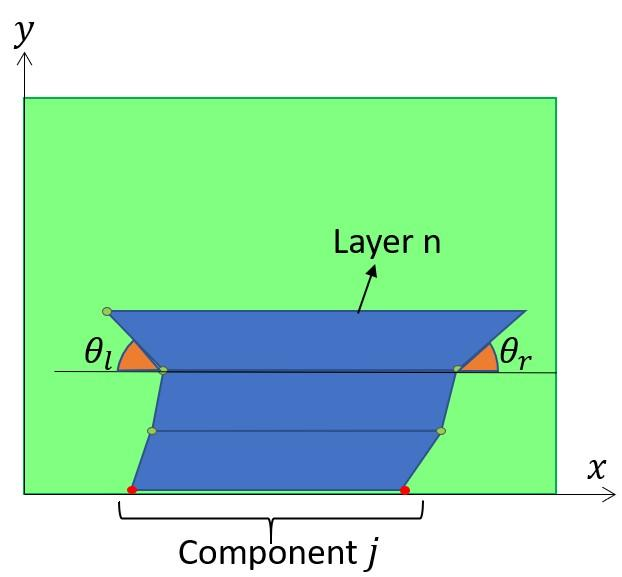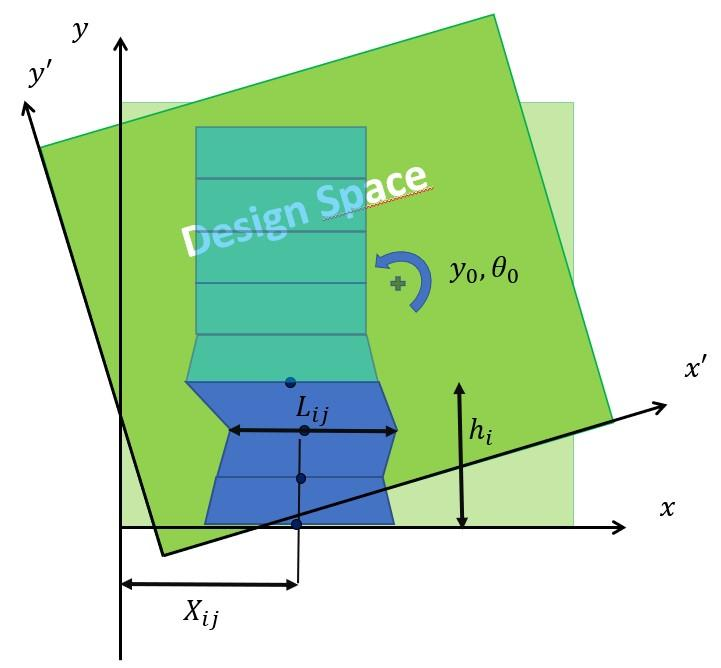

Where the primitives are characterised by a 1D node whose lateral position $x_{\textrm{ij}}$ and length $L_{\textrm{ij}}$ are the variables to be optimised. The shape of each band of component $j$ is controlled by $n$ such nodes, along with a finite print height $h_j$, which varies in case the full component length is not required. Also, the design space orientation $\theta {\;}_{0\;}$ and $y_0$ are passed as variables too as a constant bottom to top approach is not always beneficial.

## Parameters:

The syntax of the GGP_AM function is given by:

Where

- $\textrm{nelx}$ and $\textrm{nely}$ are number of elements across x and y axes respectively

- $\textrm{volfrac}$ is maximum volume fraction to be adhered to

- $\textrm{BC}$ is the boundary condition

- $\textrm{method}$ is the method of projection chosen

- $\textrm{np}$ is the number of components distributed across the design space

- $\textrm{mm}$ is the number of constraints

- $\textrm{BL}$ is the maximum bridge length

- $\textrm{theta0}$ and $\textrm{y0}$ is the initial design space orientation and longitudinal displacement.

While the choice of $\textrm{nelx},\textrm{nely},\textrm{volfrac},\textrm{np},\textrm{BL}$ are left to the users imagination, there are several options to be chosen from for the other parameters.

### Boundary Condition (BC)

As a proof of concept, there are 3 boundary conditions to be used directly, while extra inputs can definitely be added into the GGP_AM.m function. The 3 default options are:

- 'MBB' : The Messerchmitt Bolkow Blohm beam

- 'L_Shape' : The L-shaped cantilever beam

- 'Short_Cantilever' : Self explanatory.

An extra user case can be input in the function after line 205.

### Projection Method (method)

The GGP currently provides 3 projection methods from literature

- '[GP](https://www.sciencedirect.com/science/article/abs/pii/S0045782515001711?casa_token=Xr892VegDc0AAAAA:89vzo5j0SLHYUh81j6ct9CI6nLxcAElsgHH-j3wqz5d1toX4X8BYiRwC3ZdPUg8Lu_Wyf3BtltM)' : Also known as Geometric Projection, first envisioned by Julian Norato.

- '[MMC](https://link.springer.com/content/pdf/10.1007/s00158-015-1372-3.pdf)' : Moving Morphable Components, by Xu Guo and team.

- '[MNA](https://repository.tudelft.nl/islandora/object/uuid:86c056d8-f368-4239-893f-07ca3a22e112/datastream/OBJ1/download)' : Moving Node Approach, first conceptualised by J.T. Overvelde, further developed in house at ISAE SUPAERO, Toulouse (France).

### Number of Constraints (mm)

This parameter in a whole integer that provides the user the freedom to apply the constraints from a chosen set of possibilities:

- "1" : Applies only the volume fraction constraint.

- "2" : Applies the volume fraction and overhang constraint (set at 45).

- "3" : Applies the volume fraction, overhang and bridge length constraint.

### Starting point ($X_0$)

Depending upon the solution sought, it is advisable to change the intial distribution of the component in the design space. There are specifically two lines of codes that can be commented/uncommented depending upon the starting point $X_0$ required.

- Using the line 242 to obtain initial Xg provides a starting point shown in figure 1

- Using the line 244-246 to obtain initial Xg provides a starting point shown in figure 2.

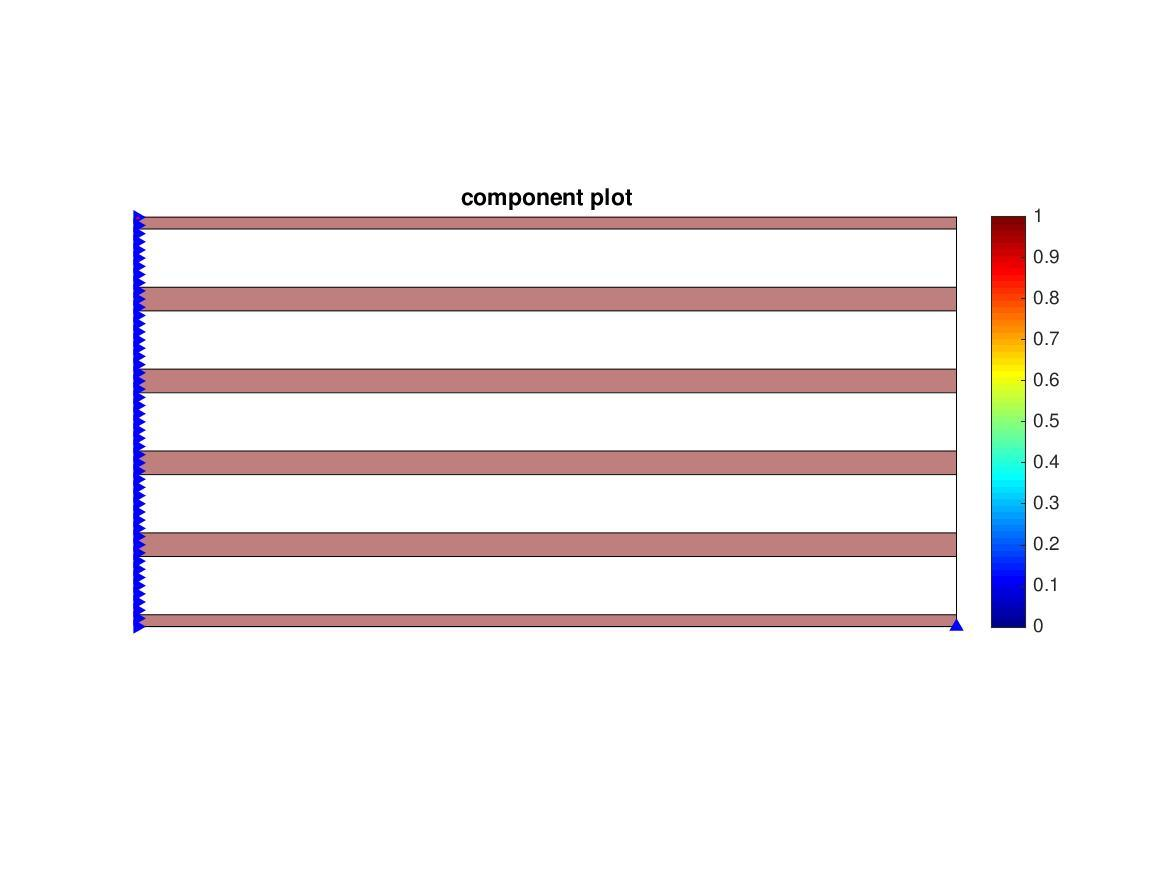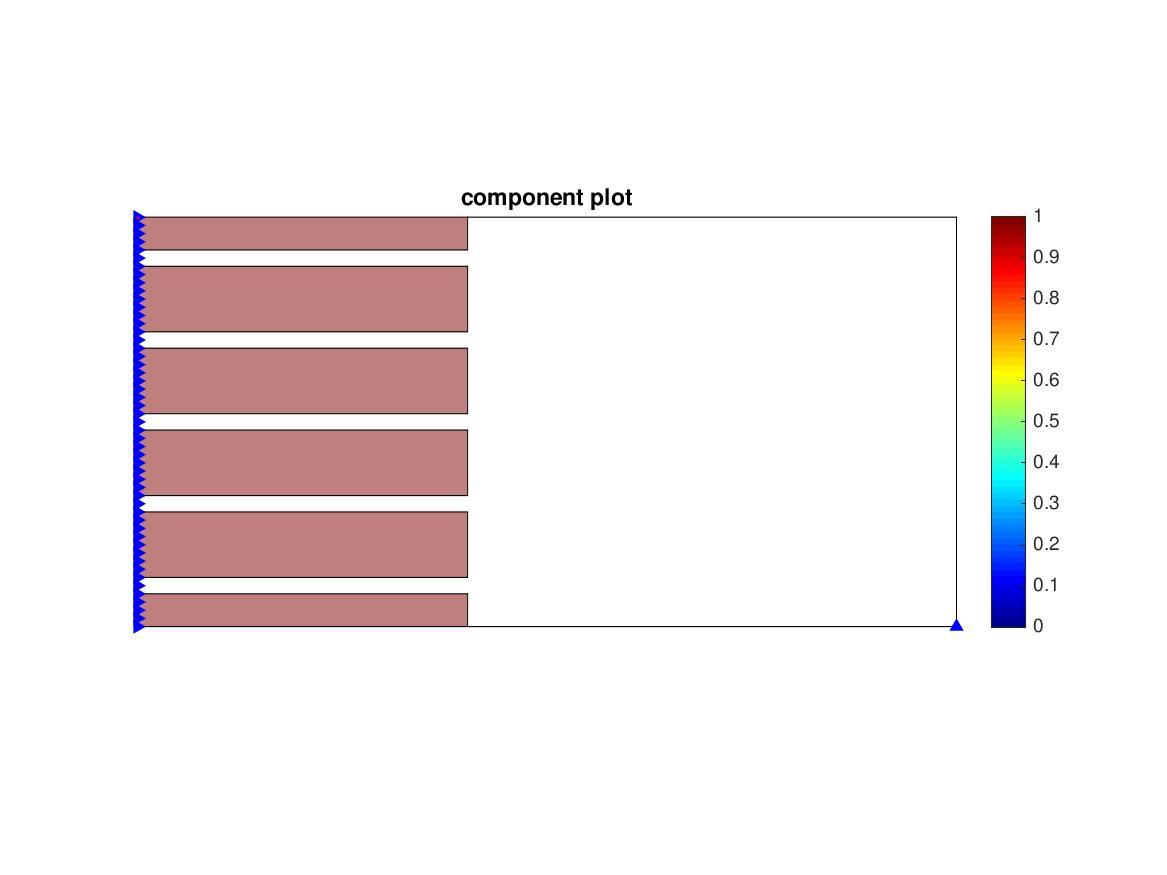

                                            Figure 1                                                                                                                                            Figure 2

For clarity, the code section is also commented to be self explanatory. It must be noted that to enable faster convergence, it's always better to start with initial conditions whose constraints are always obeyed, and hence, using the above two options will still limit the volfrac to the user input.

It is also advisable to suitable comment/uncomment lines 470-471 (if a log file of the output is required in case of HPC runs) or 472-473 (if a console output is enough to track the progress of the run). The program also creates a unique folder in which the images, log files and final variables are saved.

## EXAMPLES:

An example code to call upon the function is:

 It.:    1 Obj.:1.136e+07 Vol.:  0.429 kktnorm.: 10.001 almc.: -0.872  mtv.: -1.000 Theta: -90.00 Y0: -10.00 mbl: -10.00 ch.:  1.000 GL: 0.404 T:    2.39


 It.:    2 Obj.:1.192e+07 Vol.:  0.384 kktnorm.:73077.868 almc.: -0.436  mtv.: -0.453 Theta: -90.00 Y0: -10.00 mbl: -8.69 ch.:  0.098 GL: 0.341 T:   17.02
 It.:    3 Obj.:1.140e+07 Vol.:  0.379 kktnorm.:  7.266 almc.: -0.424  mtv.: -0.425 Theta: -90.00 Y0: -10.00 mbl: -8.38 ch.:  0.026 GL: 0.336 T:   18.09
 It.:    4 Obj.:1.134e+07 Vol.:  0.381 kktnorm.:  3.494 almc.: -0.424  mtv.: -0.425 Theta: -90.00 Y0: -10.00 mbl: -8.38 ch.:  0.008 GL: 0.340 T:   19.16
 It.:    5 Obj.:1.099e+07 Vol.:  0.382 kktnorm.:  1.574 almc.: -0.401  mtv.: -0.413 Theta: -90.00 Y0: -10.00 mbl: -8.38 ch.:  0.007 GL: 0.343 T:   20.22


 It.:    6 Obj.:1.076e+07 Vol.:  0.384 kktnorm.:  4.814 almc.: -0.211  mtv.: -0.211 Theta: -90.00 Y0: -9.95 mbl: -8.28 ch.:  0.012 GL: 0.347 T:   25.05
 It.:    7 Obj.:1.031e+07 Vol.:  0.385 kktnorm.: 12.070 almc.: -0.160  mtv.: -0.160 Theta: -90.00 Y0: -9.95 mbl: -7.38 ch.:  0.013 GL: 0.349 T:   26.05
 It.:    8 Obj.:9.526e+06 Vol.:  0.386 kktnorm.: 11.575 almc.:  0.097  mtv.:  0.096 Theta: -90.00 Y0: -9.95 mbl: -6.35 ch.:  0.016 GL: 0.349 T:   27.03
 It.:    9 Obj.:9.336e+06 Vol.:  0.387 kktnorm.: 20.390 almc.:  0.194  mtv.:  0.194 Theta: -90.00 Y0: -9.95 mbl: -5.62 ch.:  0.014 GL: 0.349 T:   28.03
 It.:   10 Obj.:8.689e+06 Vol.:  0.387 kktnorm.: 14.477 almc.:  0.191  mtv.:  0.187 Theta: -90.00 Y0: -9.95 mbl: -4.48 ch.:  0.015 GL: 0.350 T:   29.11


 It.:   11 Obj.:9.048e+06 Vol.:  0.387 kktnorm.:50228.044 almc.:  0.096  mtv.:  0.092 Theta: -90.00 Y0: -9.94 mbl: -5.38 ch.:  0.015 GL: 0.350 T:   33.57
 It.:   12 Obj.:9.065e+06 Vol.:  0.387 kktnorm.:52006.611 almc.:  0.055  mtv.:  0.055 Theta: -90.00 Y0: -9.94 mbl: -5.32 ch.:  0.004 GL: 0.350 T:   36.14
 It.:   13 Obj.:9.127e+06 Vol.:  0.387 kktnorm.:57455.155 almc.:  0.010  mtv.:  0.009 Theta: -90.00 Y0: -9.94 mbl: -5.29 ch.:  0.001 GL: 0.350 T:   37.64
 It.:   14 Obj.:8.955e+06 Vol.:  0.388 kktnorm.: 24.033 almc.: -0.005  mtv.: -0.005 Theta: -90.00 Y0: -9.94 mbl: -5.02 ch.:  0.008 GL: 0.350 T:   38.91
 It.:   15 Obj.:8.845e+06 Vol.:  0.389 kktnorm.: 10.913 almc.:  0.003  mtv.: -0.007 Theta: -90.00 Y0: -9.94 mbl: -4.73 ch.:  0.008 GL: 0.351 T:   39.93


 It.:   16 Obj.:8.802e+06 Vol.:  0.389 kktnorm.:  7.343 almc.: -0.003  mtv.: -0.009 Theta: -90.00 Y0: -9.96 mbl: -4.69 ch.:  0.007 GL: 0.352 T:   43.74
 It.:   17 Obj.:8.759e+06 Vol.:  0.390 kktnorm.:  4.883 almc.:  0.003  mtv.: -0.021 Theta: -90.00 Y0: -9.96 mbl: -4.56 ch.:  0.006 GL: 0.353 T:   44.77
 It.:   18 Obj.:8.714e+06 Vol.:  0.390 kktnorm.:  4.795 almc.: -0.000  mtv.: -0.011 Theta: -90.00 Y0: -9.96 mbl: -4.45 ch.:  0.008 GL: 0.354 T:   45.85
 It.:   19 Obj.:8.664e+06 Vol.:  0.391 kktnorm.:  6.104 almc.: -0.009  mtv.: -0.020 Theta: -90.00 Y0: -9.96 mbl: -4.39 ch.:  0.008 GL: 0.355 T:   46.85
 It.:   20 Obj.:8.573e+06 Vol.:  0.391 kktnorm.:  6.754 almc.: -0.010  mtv.: -0.016 Theta: -90.00 Y0: -9.96 mbl: -4.28 ch.:  0.008 GL: 0.356 T:   47.95


 It.:   21 Obj.:8.468e+06 Vol.:  0.391 kktnorm.:  9.285 almc.: -0.013  mtv.: -0.017 Theta: -90.00 Y0: -10.10 mbl: -4.16 ch.:  0.009 GL: 0.356 T:   51.76
 It.:   22 Obj.:8.377e+06 Vol.:  0.392 kktnorm.:  8.764 almc.: -0.016  mtv.: -0.020 Theta: -90.00 Y0: -10.10 mbl: -4.04 ch.:  0.008 GL: 0.357 T:   52.79
 It.:   23 Obj.:8.313e+06 Vol.:  0.392 kktnorm.:  5.402 almc.: -0.017  mtv.: -0.022 Theta: -90.00 Y0: -10.10 mbl: -3.90 ch.:  0.008 GL: 0.357 T:   53.81
 It.:   24 Obj.:8.238e+06 Vol.:  0.393 kktnorm.:  3.513 almc.: -0.017  mtv.: -0.023 Theta: -90.00 Y0: -10.10 mbl: -3.76 ch.:  0.007 GL: 0.358 T:   54.83
 It.:   25 Obj.:8.125e+06 Vol.:  0.393 kktnorm.:  4.541 almc.: -0.018  mtv.: -0.028 Theta: -90.00 Y0: -10.10 mbl: -3.62 ch.:  0.008 GL: 0.359 T:   56.02


 It.:   26 Obj.:7.885e+06 Vol.:  0.393 kktnorm.:  6.666 almc.: -0.012  mtv.: -0.030 Theta: -90.00 Y0: -10.43 mbl: -3.48 ch.:  0.010 GL: 0.360 T:   60.01
 It.:   27 Obj.:7.430e+06 Vol.:  0.394 kktnorm.: 14.664 almc.: -0.004  mtv.: -0.025 Theta: -90.00 Y0: -10.43 mbl: -3.26 ch.:  0.012 GL: 0.361 T:   61.00
 It.:   28 Obj.:6.814e+06 Vol.:  0.394 kktnorm.: 31.222 almc.:  0.077  mtv.:  0.075 Theta: -90.00 Y0: -10.43 mbl: -2.95 ch.:  0.014 GL: 0.362 T:   62.05
 It.:   29 Obj.:6.815e+06 Vol.:  0.394 kktnorm.: 30.259 almc.:  0.065  mtv.:  0.050 Theta: -90.00 Y0: -10.43 mbl: -3.13 ch.:  0.009 GL: 0.362 T:   63.06
 It.:   30 Obj.:6.430e+06 Vol.:  0.395 kktnorm.: 29.347 almc.:  0.144  mtv.:  0.142 Theta: -90.00 Y0: -10.43 mbl: -2.69 ch.:  0.013 GL: 0.363 T:   64.15


 It.:   31 Obj.:6.683e+06 Vol.:  0.395 kktnorm.:57242.947 almc.:  0.029  mtv.:  0.018 Theta: -90.00 Y0: -11.30 mbl: -2.89 ch.:  0.011 GL: 0.363 T:   68.95
 It.:   32 Obj.:6.625e+06 Vol.:  0.395 kktnorm.:  6.896 almc.:  0.010  mtv.: -0.004 Theta: -90.00 Y0: -11.30 mbl: -2.84 ch.:  0.006 GL: 0.364 T:   69.98
 It.:   33 Obj.:6.588e+06 Vol.:  0.396 kktnorm.:  8.377 almc.: -0.007  mtv.: -0.019 Theta: -90.00 Y0: -11.30 mbl: -2.83 ch.:  0.010 GL: 0.364 T:   71.07
 It.:   34 Obj.:6.493e+06 Vol.:  0.396 kktnorm.: 12.633 almc.: -0.010  mtv.: -0.027 Theta: -90.00 Y0: -11.30 mbl: -2.82 ch.:  0.010 GL: 0.365 T:   72.14
 It.:   35 Obj.:6.333e+06 Vol.:  0.396 kktnorm.: 20.646 almc.: -0.012  mtv.: -0.024 Theta: -90.00 Y0: -11.30 mbl: -2.81 ch.:  0.011 GL: 0.366 T:   73.20


 It.:   36 Obj.:6.144e+06 Vol.:  0.396 kktnorm.: 27.248 almc.: -0.013  mtv.: -0.020 Theta: -90.00 Y0: -11.44 mbl: -2.83 ch.:  0.012 GL: 0.366 T:   77.10
 It.:   37 Obj.:5.993e+06 Vol.:  0.397 kktnorm.: 24.719 almc.: -0.014  mtv.: -0.018 Theta: -90.00 Y0: -11.44 mbl: -2.99 ch.:  0.012 GL: 0.366 T:   78.15
 It.:   38 Obj.:5.906e+06 Vol.:  0.397 kktnorm.: 16.148 almc.: -0.013  mtv.: -0.016 Theta: -90.00 Y0: -11.44 mbl: -3.04 ch.:  0.012 GL: 0.367 T:   79.23
 It.:   39 Obj.:5.861e+06 Vol.:  0.397 kktnorm.:  9.792 almc.: -0.009  mtv.: -0.014 Theta: -90.00 Y0: -11.44 mbl: -3.31 ch.:  0.011 GL: 0.367 T:   80.30
 It.:   40 Obj.:5.799e+06 Vol.:  0.397 kktnorm.:  7.729 almc.: -0.002  mtv.: -0.003 Theta: -90.00 Y0: -11.44 mbl: -3.27 ch.:  0.011 GL: 0.367 T:   81.37


 It.:   41 Obj.:5.714e+06 Vol.:  0.397 kktnorm.: 13.562 almc.: -0.010  mtv.: -0.011 Theta: -90.00 Y0: -11.74 mbl: -3.25 ch.:  0.012 GL: 0.367 T:   85.22
 It.:   42 Obj.:5.515e+06 Vol.:  0.398 kktnorm.: 27.671 almc.: -0.013  mtv.: -0.014 Theta: -90.00 Y0: -11.74 mbl: -3.22 ch.:  0.013 GL: 0.368 T:   86.25
 It.:   43 Obj.:5.098e+06 Vol.:  0.398 kktnorm.: 62.436 almc.: -0.015  mtv.: -0.018 Theta: -90.00 Y0: -11.74 mbl: -3.18 ch.:  0.015 GL: 0.368 T:   87.28
 It.:   44 Obj.:4.485e+06 Vol.:  0.398 kktnorm.:122.417 almc.: -0.018  mtv.: -0.021 Theta: -90.00 Y0: -11.74 mbl: -3.13 ch.:  0.015 GL: 0.368 T:   88.30
 It.:   45 Obj.:3.792e+06 Vol.:  0.398 kktnorm.:151.416 almc.:  0.009  mtv.: -0.001 Theta: -90.00 Y0: -11.74 mbl: -3.08 ch.:  0.016 GL: 0.368 T:   89.47


 It.:   46 Obj.:2.693e+06 Vol.:  0.398 kktnorm.:168.562 almc.:  0.098  mtv.:  0.098 Theta: -90.00 Y0: -11.53 mbl: -2.99 ch.:  0.016 GL: 0.368 T:   93.80
 It.:   47 Obj.:2.815e+06 Vol.:  0.398 kktnorm.:204.709 almc.: -0.003  mtv.: -0.016 Theta: -90.00 Y0: -11.53 mbl: -2.85 ch.:  0.015 GL: 0.369 T:   94.91
 It.:   48 Obj.:2.563e+06 Vol.:  0.398 kktnorm.: 74.268 almc.:  0.001  mtv.: -0.002 Theta: -90.00 Y0: -11.53 mbl: -2.87 ch.:  0.015 GL: 0.369 T:   96.07
 It.:   49 Obj.:2.476e+06 Vol.:  0.399 kktnorm.: 51.892 almc.: -0.015  mtv.: -0.020 Theta: -90.00 Y0: -11.53 mbl: -2.84 ch.:  0.015 GL: 0.369 T:   97.16
 It.:   50 Obj.:2.368e+06 Vol.:  0.399 kktnorm.: 53.529 almc.: -0.019  mtv.: -0.022 Theta: -90.00 Y0: -11.53 mbl: -2.87 ch.:  0.015 GL: 0.369 T:   98.23


 It.:   51 Obj.:2.214e+06 Vol.:  0.399 kktnorm.: 73.385 almc.: -0.021  mtv.: -0.023 Theta: -90.00 Y0: -11.94 mbl: -2.88 ch.:  0.015 GL: 0.369 T:  102.27
 It.:   52 Obj.:1.573e+06 Vol.:  0.399 kktnorm.:119.313 almc.: -0.025  mtv.: -0.026 Theta: -90.00 Y0: -11.94 mbl: -2.75 ch.:  0.015 GL: 0.369 T:  103.36
 It.:   53 Obj.:9.644e+05 Vol.:  0.399 kktnorm.:269.235 almc.: -0.027  mtv.: -0.028 Theta: -90.00 Y0: -11.94 mbl: -2.60 ch.:  0.014 GL: 0.370 T:  104.45
 It.:   54 Obj.:4.217e+05 Vol.:  0.400 kktnorm.:432.257 almc.: -0.031  mtv.: -0.032 Theta: -90.00 Y0: -11.94 mbl: -2.44 ch.:  0.014 GL: 0.370 T:  105.57
 It.:   55 Obj.:1.418e+05 Vol.:  0.400 kktnorm.:548.293 almc.: -0.037  mtv.: -0.038 Theta: -90.00 Y0: -11.94 mbl: -2.24 ch.:  0.014 GL: 0.370 T:  106.66


 It.:   56 Obj.:4.309e+04 Vol.:  0.399 kktnorm.:563.913 almc.: -0.044  mtv.: -0.046 Theta: -90.00 Y0: -12.05 mbl: -2.02 ch.:  0.014 GL: 0.370 T:  110.75
 It.:   57 Obj.:1.488e+04 Vol.:  0.399 kktnorm.:503.877 almc.: -0.047  mtv.: -0.058 Theta: -90.00 Y0: -12.05 mbl: -1.75 ch.:  0.015 GL: 0.369 T:  111.80
 It.:   58 Obj.:5.375e+03 Vol.:  0.397 kktnorm.:548.673 almc.:  0.006  mtv.: -0.003 Theta: -90.00 Y0: -12.05 mbl: -1.36 ch.:  0.020 GL: 0.363 T:  112.85
 It.:   59 Obj.:2.022e+03 Vol.:  0.395 kktnorm.:633.060 almc.:  0.245  mtv.:  0.245 Theta: -90.00 Y0: -12.05 mbl: -0.67 ch.:  0.027 GL: 0.357 T:  114.04
 It.:   60 Obj.:2.709e+03 Vol.:  0.395 kktnorm.:632.345 almc.:  0.083  mtv.:  0.066 Theta: -90.00 Y0: -12.05 mbl: -1.47 ch.:  0.020 GL: 0.355 T:  115.20


 It.:   61 Obj.:1.085e+03 Vol.:  0.394 kktnorm.:419.235 almc.:  0.120  mtv.:  0.114 Theta: -90.00 Y0: -12.03 mbl: -1.04 ch.:  0.019 GL: 0.353 T:  119.54
 It.:   62 Obj.:6.575e+02 Vol.:  0.394 kktnorm.:283.693 almc.:  0.148  mtv.:  0.146 Theta: -90.00 Y0: -12.03 mbl: -0.83 ch.:  0.023 GL: 0.350 T:  120.83
 It.:   63 Obj.:1.076e+03 Vol.:  0.394 kktnorm.:57552.768 almc.:  0.073  mtv.:  0.056 Theta: -90.00 Y0: -12.03 mbl: -0.98 ch.:  0.012 GL: 0.350 T:  122.29
 It.:   64 Obj.:1.409e+03 Vol.:  0.394 kktnorm.:43196.377 almc.:  0.050  mtv.:  0.041 Theta: -90.00 Y0: -12.03 mbl: -1.02 ch.:  0.007 GL: 0.350 T:  123.81
 It.:   65 Obj.:2.014e+03 Vol.:  0.394 kktnorm.:45925.245 almc.:  0.027  mtv.:  0.023 Theta: -90.00 Y0: -12.03 mbl: -1.07 ch.:  0.006 GL: 0.350 T:  125.36


 It.:   66 Obj.:3.093e+03 Vol.:  0.394 kktnorm.:50697.764 almc.:  0.003  mtv.:  0.001 Theta: -90.00 Y0: -12.05 mbl: -1.12 ch.:  0.006 GL: 0.350 T:  130.06
 It.:   67 Obj.:1.757e+03 Vol.:  0.395 kktnorm.:917.533 almc.: -0.005  mtv.: -0.023 Theta: -90.00 Y0: -12.05 mbl: -0.99 ch.:  0.010 GL: 0.350 T:  131.49
 It.:   68 Obj.:1.472e+03 Vol.:  0.397 kktnorm.:465.563 almc.: -0.008  mtv.: -0.017 Theta: -90.00 Y0: -12.05 mbl: -0.92 ch.:  0.014 GL: 0.351 T:  132.79
 It.:   69 Obj.:1.263e+03 Vol.:  0.399 kktnorm.:394.163 almc.: -0.007  mtv.: -0.014 Theta: -90.00 Y0: -12.05 mbl: -0.86 ch.:  0.014 GL: 0.352 T:  134.30
 It.:   70 Obj.:1.110e+03 Vol.:  0.399 kktnorm.:343.440 almc.: -0.008  mtv.: -0.015 Theta: -90.00 Y0: -12.05 mbl: -0.83 ch.:  0.012 GL: 0.352 T:  135.62


 It.:   71 Obj.:9.646e+02 Vol.:  0.399 kktnorm.:319.119 almc.: -0.009  mtv.: -0.017 Theta: -90.00 Y0: -12.01 mbl: -0.78 ch.:  0.013 GL: 0.352 T:  139.70
 It.:   72 Obj.:8.394e+02 Vol.:  0.399 kktnorm.:291.323 almc.: -0.010  mtv.: -0.020 Theta: -90.00 Y0: -12.01 mbl: -0.75 ch.:  0.012 GL: 0.351 T:  141.25
 It.:   73 Obj.:7.247e+02 Vol.:  0.399 kktnorm.:258.937 almc.: -0.010  mtv.: -0.025 Theta: -90.00 Y0: -12.01 mbl: -0.72 ch.:  0.014 GL: 0.350 T:  142.69
 It.:   74 Obj.:5.504e+02 Vol.:  0.394 kktnorm.:267.657 almc.:  0.041  mtv.:  0.034 Theta: -90.00 Y0: -12.01 mbl: -0.62 ch.:  0.022 GL: 0.344 T:  144.03
 It.:   75 Obj.:3.760e+02 Vol.:  0.394 kktnorm.:215.611 almc.:  0.123  mtv.:  0.112 Theta: -90.00 Y0: -12.01 mbl: -0.42 ch.:  0.025 GL: 0.343 T:  145.46


 It.:   76 Obj.:2.859e+02 Vol.:  0.392 kktnorm.:106.731 almc.:  0.221  mtv.:  0.211 Theta: -90.00 Y0: -11.97 mbl: -0.23 ch.:  0.026 GL: 0.343 T:  149.61
 It.:   77 Obj.:3.446e+02 Vol.:  0.393 kktnorm.:43752.198 almc.:  0.045  mtv.:  0.029 Theta: -90.00 Y0: -11.97 mbl: -0.40 ch.:  0.015 GL: 0.343 T:  150.75
 It.:   78 Obj.:4.060e+02 Vol.:  0.394 kktnorm.:38210.680 almc.: -0.013  mtv.: -0.038 Theta: -90.00 Y0: -11.97 mbl: -0.55 ch.:  0.013 GL: 0.344 T:  152.60
 It.:   79 Obj.:3.422e+02 Vol.:  0.395 kktnorm.:126.792 almc.:  0.158  mtv.:  0.158 Theta: -90.00 Y0: -11.97 mbl: -0.48 ch.:  0.021 GL: 0.345 T:  154.02
 It.:   80 Obj.:1.825e+02 Vol.:  0.395 kktnorm.:57958.914 almc.:  0.018  mtv.:  0.006 Theta: -90.00 Y0: -11.97 mbl: -0.47 ch.:  0.005 GL: 0.345 T:  155.20


 It.:   81 Obj.:1.809e+02 Vol.:  0.397 kktnorm.:156.069 almc.: -0.007  mtv.: -0.038 Theta: -90.00 Y0: -12.00 mbl: -0.47 ch.:  0.014 GL: 0.347 T:  159.32
 It.:   82 Obj.:1.745e+02 Vol.:  0.397 kktnorm.: 39.370 almc.: -0.007  mtv.: -0.035 Theta: -90.00 Y0: -12.00 mbl: -0.45 ch.:  0.019 GL: 0.345 T:  160.49
 It.:   83 Obj.:1.690e+02 Vol.:  0.397 kktnorm.: 40.890 almc.:  0.034  mtv.:  0.029 Theta: -90.00 Y0: -12.00 mbl: -0.44 ch.:  0.019 GL: 0.344 T:  161.61
 It.:   84 Obj.:1.626e+02 Vol.:  0.397 kktnorm.: 44.681 almc.:  0.061  mtv.:  0.057 Theta: -90.00 Y0: -12.00 mbl: -0.41 ch.:  0.019 GL: 0.344 T:  163.08
 It.:   85 Obj.:1.557e+02 Vol.:  0.397 kktnorm.: 39.219 almc.:  0.131  mtv.:  0.122 Theta: -90.00 Y0: -12.00 mbl: -0.38 ch.:  0.019 GL: 0.344 T:  164.53


 It.:   86 Obj.:1.488e+02 Vol.:  0.397 kktnorm.: 38.839 almc.:  0.124  mtv.:  0.117 Theta: -90.00 Y0: -11.97 mbl: -0.34 ch.:  0.019 GL: 0.343 T:  168.99
 It.:   87 Obj.:1.485e+02 Vol.:  0.389 kktnorm.:1259.446 almc.:  0.203  mtv.:  0.203 Theta: -90.00 Y0: -11.97 mbl: -0.34 ch.:  0.017 GL: 0.338 T:  170.30
 It.:   88 Obj.:1.415e+02 Vol.:  0.394 kktnorm.: 39.554 almc.:  0.057  mtv.:  0.023 Theta: -90.00 Y0: -11.97 mbl: -0.28 ch.:  0.018 GL: 0.340 T:  171.71
 It.:   89 Obj.:1.439e+02 Vol.:  0.393 kktnorm.:25516.881 almc.:  0.036  mtv.:  0.015 Theta: -90.00 Y0: -11.97 mbl: -0.34 ch.:  0.017 GL: 0.340 T:  173.62
 It.:   90 Obj.:1.444e+02 Vol.:  0.394 kktnorm.:28913.030 almc.:  0.022  mtv.: -0.003 Theta: -90.00 Y0: -11.97 mbl: -0.37 ch.:  0.011 GL: 0.341 T:  175.56


 It.:   91 Obj.:1.451e+02 Vol.:  0.395 kktnorm.:24470.762 almc.:  0.011  mtv.: -0.017 Theta: -90.00 Y0: -11.98 mbl: -0.39 ch.:  0.010 GL: 0.341 T:  180.48
 It.:   92 Obj.:1.459e+02 Vol.:  0.395 kktnorm.:22435.457 almc.:  0.000  mtv.: -0.023 Theta: -90.00 Y0: -11.98 mbl: -0.41 ch.:  0.009 GL: 0.341 T:  182.17
 It.:   93 Obj.:1.424e+02 Vol.:  0.396 kktnorm.: 45.041 almc.: -0.004  mtv.: -0.032 Theta: -90.00 Y0: -11.98 mbl: -0.39 ch.:  0.011 GL: 0.342 T:  183.51
 It.:   94 Obj.:1.392e+02 Vol.:  0.397 kktnorm.: 44.418 almc.: -0.006  mtv.: -0.035 Theta: -90.00 Y0: -11.98 mbl: -0.37 ch.:  0.012 GL: 0.342 T:  184.93
 It.:   95 Obj.:1.361e+02 Vol.:  0.398 kktnorm.: 43.781 almc.: -0.007  mtv.: -0.039 Theta: -90.00 Y0: -11.98 mbl: -0.35 ch.:  0.013 GL: 0.342 T:  186.30


 It.:   96 Obj.:1.327e+02 Vol.:  0.398 kktnorm.: 42.870 almc.: -0.008  mtv.: -0.044 Theta: -90.00 Y0: -12.00 mbl: -0.33 ch.:  0.013 GL: 0.342 T:  190.72
 It.:   97 Obj.:1.291e+02 Vol.:  0.399 kktnorm.: 41.691 almc.: -0.003  mtv.: -0.041 Theta: -90.00 Y0: -12.00 mbl: -0.30 ch.:  0.014 GL: 0.341 T:  191.90
 It.:   98 Obj.:1.250e+02 Vol.:  0.399 kktnorm.: 40.798 almc.:  0.002  mtv.: -0.041 Theta: -90.00 Y0: -12.00 mbl: -0.26 ch.:  0.014 GL: 0.341 T:  193.35
 It.:   99 Obj.:1.213e+02 Vol.:  0.399 kktnorm.: 38.185 almc.:  0.003  mtv.: -0.035 Theta: -90.00 Y0: -12.00 mbl: -0.22 ch.:  0.016 GL: 0.340 T:  194.43
 It.:  100 Obj.:1.183e+02 Vol.:  0.399 kktnorm.: 31.423 almc.: -0.001  mtv.: -0.033 Theta: -90.00 Y0: -12.00 mbl: -0.20 ch.:  0.014 GL: 0.340 T:  195.50


 It.:  101 Obj.:1.156e+02 Vol.:  0.399 kktnorm.: 26.599 almc.: -0.004  mtv.: -0.036 Theta: -90.00 Y0: -12.02 mbl: -0.18 ch.:  0.014 GL: 0.340 T:  199.72
 It.:  102 Obj.:1.125e+02 Vol.:  0.399 kktnorm.: 27.505 almc.: -0.005  mtv.: -0.034 Theta: -90.00 Y0: -12.02 mbl: -0.16 ch.:  0.015 GL: 0.340 T:  200.81
 It.:  103 Obj.:1.094e+02 Vol.:  0.399 kktnorm.: 25.322 almc.: -0.005  mtv.: -0.034 Theta: -90.00 Y0: -12.02 mbl: -0.14 ch.:  0.014 GL: 0.340 T:  201.88
 It.:  104 Obj.:1.064e+02 Vol.:  0.399 kktnorm.: 23.906 almc.: -0.006  mtv.: -0.034 Theta: -90.00 Y0: -12.02 mbl: -0.11 ch.:  0.014 GL: 0.340 T:  202.92
 It.:  105 Obj.:1.033e+02 Vol.:  0.399 kktnorm.: 22.789 almc.: -0.006  mtv.: -0.034 Theta: -90.00 Y0: -12.02 mbl: -0.09 ch.:  0.014 GL: 0.340 T:  203.98
 It.:  106 Obj.:1.001e+02 Vol.:  0.399 kktnorm.: 22.033 almc.: -0.007  mtv.: -0.035 Theta: -90.00 Y0: -12.02 mbl: -0.06 ch.:  0.014 GL: 0.341 T:  205.01
 It.:  107 Obj.:9.700e+01 Vol.:  0.399 kktnorm.: 21.322 almc.: -0.008  mtv.: -0.03

 It.:  121 Obj.:7.964e+01 Vol.:  0.392 kktnorm.:136769.861 almc.: -0.010  mtv.: -0.061 Theta: -89.86 Y0: -12.24 mbl: -0.00 ch.:  0.008 GL: 0.333 T:  226.90
 It.:  122 Obj.:7.511e+01 Vol.:  0.395 kktnorm.: 27.942 almc.: -0.003  mtv.: -0.050 Theta: -89.86 Y0: -12.24 mbl: 0.00 ch.:  0.010 GL: 0.335 T:  228.12
 It.:  123 Obj.:7.456e+01 Vol.:  0.397 kktnorm.: 39.430 almc.: -0.001  mtv.: -0.044 Theta: -89.86 Y0: -12.24 mbl: -0.00 ch.:  0.004 GL: 0.336 T:  229.54
 It.:  124 Obj.:7.409e+01 Vol.:  0.398 kktnorm.:  6.545 almc.: -0.001  mtv.: -0.041 Theta: -89.86 Y0: -12.24 mbl: -0.00 ch.:  0.004 GL: 0.338 T:  230.90
 It.:  125 Obj.:7.371e+01 Vol.:  0.399 kktnorm.:  5.637 almc.: -0.002  mtv.: -0.039 Theta: -89.86 Y0: -12.24 mbl: -0.00 ch.:  0.004 GL: 0.339 T:  232.17
 It.:  126 Obj.:7.330e+01 Vol.:  0.400 kktnorm.:  5.351 almc.: -0.002  mtv.: -0.037 Theta: -89.86 Y0: -12.24 mbl: -0.00 ch.:  0.004 GL: 0.340 T:  233.44
 It.:  127 Obj.:7.292e+01 Vol.:  0.400 kktnorm.:  5.279 almc.: -0.002  mtv.: -0.

 It.:  141 Obj.:6.692e+01 Vol.:  0.400 kktnorm.: 11.761 almc.: -0.002  mtv.: -0.051 Theta: -90.00 Y0: -12.47 mbl: 0.00 ch.:  0.010 GL: 0.339 T:  254.39
 It.:  142 Obj.:6.649e+01 Vol.:  0.400 kktnorm.: 12.769 almc.:  0.001  mtv.: -0.045 Theta: -90.00 Y0: -12.47 mbl: 0.00 ch.:  0.010 GL: 0.339 T:  255.50
 It.:  143 Obj.:6.594e+01 Vol.:  0.400 kktnorm.:  5.886 almc.:  0.005  mtv.: -0.047 Theta: -90.00 Y0: -12.47 mbl: 0.01 ch.:  0.011 GL: 0.339 T:  256.59
 It.:  144 Obj.:6.538e+01 Vol.:  0.400 kktnorm.: 18.983 almc.:  0.009  mtv.: -0.036 Theta: -90.00 Y0: -12.47 mbl: 0.00 ch.:  0.012 GL: 0.339 T:  257.71
 It.:  145 Obj.:6.512e+01 Vol.:  0.400 kktnorm.: 13.451 almc.:  0.020  mtv.:  0.005 Theta: -90.00 Y0: -12.47 mbl: -0.00 ch.:  0.011 GL: 0.339 T:  258.90
 It.:  146 Obj.:6.409e+01 Vol.:  0.399 kktnorm.:  6.356 almc.:  0.153  mtv.:  0.152 Theta: -90.00 Y0: -12.47 mbl: 0.02 ch.:  0.013 GL: 0.339 T:  260.04
 It.:  147 Obj.:6.337e+01 Vol.:  0.399 kktnorm.: 15.910 almc.:  0.079  mtv.:  0.055 The

 It.:  155 Obj.:6.472e+01 Vol.:  0.399 kktnorm.:24157.216 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.47 mbl: -0.02 ch.:  0.001 GL: 0.338 T:  275.33
 It.:  156 Obj.:6.428e+01 Vol.:  0.400 kktnorm.: 15.373 almc.: -0.001  mtv.: -0.050 Theta: -90.00 Y0: -12.47 mbl: 0.01 ch.:  0.007 GL: 0.339 T:  276.74
 It.:  157 Obj.:6.434e+01 Vol.:  0.400 kktnorm.:97162.285 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -12.47 mbl: -0.00 ch.:  0.000 GL: 0.339 T:  278.76
 It.:  158 Obj.:6.419e+01 Vol.:  0.400 kktnorm.:359.315 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -12.47 mbl: -0.01 ch.:  0.003 GL: 0.338 T:  280.24
 It.:  159 Obj.:6.379e+01 Vol.:  0.400 kktnorm.: 15.365 almc.: -0.001  mtv.: -0.048 Theta: -90.00 Y0: -12.47 mbl: 0.01 ch.:  0.006 GL: 0.338 T:  281.34
 It.:  160 Obj.:6.393e+01 Vol.:  0.400 kktnorm.:112334.648 almc.: -0.000  mtv.: -0.044 Theta: -90.00 Y0: -12.47 mbl: -0.01 ch.:  0.002 GL: 0.338 T:  283.21


 It.:  161 Obj.:6.319e+01 Vol.:  0.400 kktnorm.: 17.310 almc.: -0.000  mtv.: -0.041 Theta: -90.00 Y0: -12.49 mbl: 0.00 ch.:  0.008 GL: 0.338 T:  288.30
 It.:  162 Obj.:6.287e+01 Vol.:  0.400 kktnorm.:529.194 almc.:  0.000  mtv.: -0.043 Theta: -90.00 Y0: -12.49 mbl: -0.02 ch.:  0.006 GL: 0.337 T:  289.69
 It.:  163 Obj.:6.251e+01 Vol.:  0.400 kktnorm.: 15.687 almc.:  0.099  mtv.:  0.098 Theta: -90.00 Y0: -12.49 mbl: 0.01 ch.:  0.005 GL: 0.337 T:  290.90
 It.:  164 Obj.:6.265e+01 Vol.:  0.399 kktnorm.:105337.417 almc.:  0.012  mtv.: -0.028 Theta: -90.00 Y0: -12.49 mbl: -0.01 ch.:  0.003 GL: 0.337 T:  293.15
 It.:  165 Obj.:6.257e+01 Vol.:  0.400 kktnorm.: 16.833 almc.:  0.005  mtv.: -0.039 Theta: -90.00 Y0: -12.49 mbl: 0.00 ch.:  0.002 GL: 0.337 T:  294.49
 It.:  166 Obj.:6.291e+01 Vol.:  0.400 kktnorm.:122572.419 almc.: -0.000  mtv.: -0.039 Theta: -90.00 Y0: -12.49 mbl: 0.04 ch.:  0.004 GL: 0.337 T:  296.37
 It.:  167 Obj.:6.299e+01 Vol.:  0.400 kktnorm.:122399.865 almc.: -0.000  mtv.: 

 It.:  181 Obj.:6.159e+01 Vol.:  0.400 kktnorm.:  5.030 almc.: -0.002  mtv.: -0.053 Theta: -90.00 Y0: -12.56 mbl: -0.00 ch.:  0.003 GL: 0.338 T:  319.35
 It.:  182 Obj.:6.141e+01 Vol.:  0.400 kktnorm.:  4.515 almc.: -0.002  mtv.: -0.052 Theta: -90.00 Y0: -12.56 mbl: -0.00 ch.:  0.003 GL: 0.338 T:  320.36
 It.:  183 Obj.:6.118e+01 Vol.:  0.400 kktnorm.:  4.012 almc.:  0.001  mtv.: -0.038 Theta: -90.00 Y0: -12.56 mbl: -0.00 ch.:  0.003 GL: 0.338 T:  321.39
 It.:  184 Obj.:6.092e+01 Vol.:  0.400 kktnorm.:  4.195 almc.:  0.009  mtv.: -0.033 Theta: -90.00 Y0: -12.56 mbl: -0.00 ch.:  0.003 GL: 0.338 T:  322.41
 It.:  185 Obj.:6.075e+01 Vol.:  0.400 kktnorm.:  5.373 almc.:  0.007  mtv.: -0.028 Theta: -90.00 Y0: -12.56 mbl: 0.03 ch.:  0.005 GL: 0.338 T:  323.41
 It.:  186 Obj.:6.026e+01 Vol.:  0.400 kktnorm.: 14.814 almc.:  0.008  mtv.: -0.045 Theta: -90.00 Y0: -12.56 mbl: 0.03 ch.:  0.004 GL: 0.338 T:  324.49
 It.:  187 Obj.:6.125e+01 Vol.:  0.399 kktnorm.:86946.272 almc.: -0.001  mtv.: -0.05

 It.:  201 Obj.:5.940e+01 Vol.:  0.400 kktnorm.:  3.152 almc.:  0.001  mtv.: -0.047 Theta: -90.00 Y0: -12.60 mbl: -0.00 ch.:  0.005 GL: 0.339 T:  346.27
 It.:  202 Obj.:5.918e+01 Vol.:  0.400 kktnorm.:  2.990 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.60 mbl: -0.00 ch.:  0.006 GL: 0.339 T:  347.29
 It.:  203 Obj.:5.886e+01 Vol.:  0.400 kktnorm.:  2.461 almc.:  0.003  mtv.: -0.053 Theta: -90.00 Y0: -12.60 mbl: 0.13 ch.:  0.007 GL: 0.339 T:  348.36
 It.:  204 Obj.:5.829e+01 Vol.:  0.400 kktnorm.: 15.194 almc.:  0.012  mtv.: -0.029 Theta: -90.00 Y0: -12.60 mbl: 0.11 ch.:  0.009 GL: 0.338 T:  349.40
 It.:  205 Obj.:5.878e+01 Vol.:  0.398 kktnorm.:79478.029 almc.:  0.017  mtv.: -0.023 Theta: -90.00 Y0: -12.60 mbl: 0.01 ch.:  0.007 GL: 0.336 T:  350.98
 It.:  206 Obj.:5.903e+01 Vol.:  0.399 kktnorm.:64979.479 almc.:  0.006  mtv.: -0.042 Theta: -90.00 Y0: -12.60 mbl: 0.00 ch.:  0.002 GL: 0.337 T:  352.88
 It.:  207 Obj.:5.924e+01 Vol.:  0.399 kktnorm.:69686.548 almc.: -0.001  mtv.: -0.

 It.:  221 Obj.:5.766e+01 Vol.:  0.400 kktnorm.:  6.665 almc.: -0.001  mtv.: -0.056 Theta: -90.00 Y0: -12.57 mbl: -0.02 ch.:  0.008 GL: 0.339 T:  374.41
 It.:  222 Obj.:5.742e+01 Vol.:  0.400 kktnorm.:  7.848 almc.:  0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.57 mbl: 0.02 ch.:  0.008 GL: 0.339 T:  375.43
 It.:  223 Obj.:5.686e+01 Vol.:  0.399 kktnorm.: 12.517 almc.:  0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.57 mbl: 0.40 ch.:  0.009 GL: 0.339 T:  376.45
 It.:  224 Obj.:5.808e+01 Vol.:  0.396 kktnorm.:141885.027 almc.:  0.021  mtv.: -0.009 Theta: -90.00 Y0: -12.57 mbl: 0.24 ch.:  0.015 GL: 0.336 T:  377.50
 It.:  225 Obj.:5.834e+01 Vol.:  0.396 kktnorm.:94784.358 almc.:  0.025  mtv.:  0.012 Theta: -90.00 Y0: -12.57 mbl: 0.07 ch.:  0.007 GL: 0.335 T:  378.82
 It.:  226 Obj.:5.830e+01 Vol.:  0.397 kktnorm.:71181.810 almc.:  0.005  mtv.: -0.048 Theta: -90.00 Y0: -12.57 mbl: 0.01 ch.:  0.002 GL: 0.336 T:  380.54
 It.:  227 Obj.:5.859e+01 Vol.:  0.397 kktnorm.:70653.476 almc.: -0.001  mtv.: -

 It.:  241 Obj.:5.674e+01 Vol.:  0.400 kktnorm.:108999.716 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -12.57 mbl: -0.01 ch.:  0.001 GL: 0.339 T:  408.54
 It.:  242 Obj.:5.659e+01 Vol.:  0.400 kktnorm.: 10.715 almc.: -0.001  mtv.: -0.056 Theta: -90.00 Y0: -12.57 mbl: 0.01 ch.:  0.003 GL: 0.339 T:  409.66
 It.:  243 Obj.:5.663e+01 Vol.:  0.400 kktnorm.:110508.670 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -12.57 mbl: -0.00 ch.:  0.001 GL: 0.339 T:  411.71
 It.:  244 Obj.:5.664e+01 Vol.:  0.400 kktnorm.:106876.861 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -12.57 mbl: -0.02 ch.:  0.001 GL: 0.339 T:  413.85
 It.:  245 Obj.:5.653e+01 Vol.:  0.400 kktnorm.: 10.645 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -12.57 mbl: 0.00 ch.:  0.003 GL: 0.339 T:  415.03
 It.:  246 Obj.:5.657e+01 Vol.:  0.400 kktnorm.:109255.661 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -12.57 mbl: -0.01 ch.:  0.001 GL: 0.339 T:  417.12
 It.:  247 Obj.:5.647e+01 Vol.:  0.400 kktnorm.: 10.648 almc.: -0.000  m

 It.:  261 Obj.:5.616e+01 Vol.:  0.400 kktnorm.:  9.873 almc.: -0.000  mtv.: -0.056 Theta: -90.00 Y0: -12.58 mbl: -0.02 ch.:  0.001 GL: 0.339 T:  445.07
 It.:  262 Obj.:5.622e+01 Vol.:  0.400 kktnorm.:94899.570 almc.: -0.000  mtv.: -0.057 Theta: -90.00 Y0: -12.58 mbl: -0.03 ch.:  0.002 GL: 0.339 T:  447.37
 It.:  263 Obj.:5.612e+01 Vol.:  0.400 kktnorm.:  9.768 almc.: -0.000  mtv.: -0.056 Theta: -90.00 Y0: -12.58 mbl: -0.02 ch.:  0.001 GL: 0.339 T:  448.59
 It.:  264 Obj.:5.607e+01 Vol.:  0.400 kktnorm.: 65.376 almc.: -0.000  mtv.: -0.056 Theta: -90.00 Y0: -12.58 mbl: -0.03 ch.:  0.002 GL: 0.339 T:  450.05
 It.:  265 Obj.:5.600e+01 Vol.:  0.400 kktnorm.:  9.203 almc.: -0.000  mtv.: -0.056 Theta: -90.00 Y0: -12.58 mbl: -0.02 ch.:  0.001 GL: 0.339 T:  451.16
 It.:  266 Obj.:5.611e+01 Vol.:  0.400 kktnorm.:67324.213 almc.: -0.000  mtv.: -0.056 Theta: -90.00 Y0: -12.58 mbl: -0.03 ch.:  0.003 GL: 0.339 T:  453.13
 It.:  267 Obj.:5.599e+01 Vol.:  0.400 kktnorm.: 10.000 almc.: -0.000  mtv.: -

 It.:  281 Obj.:5.443e+01 Vol.:  0.400 kktnorm.:  4.431 almc.: -0.002  mtv.: -0.057 Theta: -90.00 Y0: -12.62 mbl: -0.03 ch.:  0.005 GL: 0.339 T:  473.46
 It.:  282 Obj.:5.421e+01 Vol.:  0.400 kktnorm.:  3.869 almc.: -0.002  mtv.: -0.057 Theta: -90.00 Y0: -12.62 mbl: -0.03 ch.:  0.005 GL: 0.339 T:  474.45
 It.:  283 Obj.:5.398e+01 Vol.:  0.400 kktnorm.:  3.266 almc.: -0.002  mtv.: -0.057 Theta: -90.00 Y0: -12.62 mbl: -0.03 ch.:  0.005 GL: 0.339 T:  475.45
 It.:  284 Obj.:5.374e+01 Vol.:  0.400 kktnorm.:  2.620 almc.: -0.002  mtv.: -0.056 Theta: -90.00 Y0: -12.62 mbl: -0.02 ch.:  0.006 GL: 0.339 T:  476.43
 It.:  285 Obj.:5.352e+01 Vol.:  0.400 kktnorm.:  1.994 almc.:  0.015  mtv.: -0.004 Theta: -90.00 Y0: -12.62 mbl: -0.02 ch.:  0.007 GL: 0.338 T:  477.41
 It.:  286 Obj.:5.270e+01 Vol.:  0.399 kktnorm.:  3.406 almc.:  0.162  mtv.:  0.157 Theta: -90.00 Y0: -12.62 mbl: 0.11 ch.:  0.012 GL: 0.337 T:  478.39
 It.:  287 Obj.:5.337e+01 Vol.:  0.397 kktnorm.:49233.173 almc.:  0.085  mtv.:  0.0

 It.:  301 Obj.:5.267e+01 Vol.:  0.400 kktnorm.:  1.561 almc.: -0.001  mtv.: -0.058 Theta: -90.00 Y0: -12.63 mbl: -0.03 ch.:  0.007 GL: 0.335 T:  499.24
 It.:  302 Obj.:5.255e+01 Vol.:  0.400 kktnorm.:  1.530 almc.: -0.001  mtv.: -0.058 Theta: -90.00 Y0: -12.63 mbl: -0.03 ch.:  0.007 GL: 0.335 T:  500.20
 It.:  303 Obj.:5.242e+01 Vol.:  0.400 kktnorm.:  1.513 almc.: -0.001  mtv.: -0.059 Theta: -90.00 Y0: -12.63 mbl: -0.03 ch.:  0.008 GL: 0.335 T:  501.23
 It.:  304 Obj.:5.226e+01 Vol.:  0.400 kktnorm.:  1.518 almc.: -0.001  mtv.: -0.058 Theta: -90.00 Y0: -12.63 mbl: -0.03 ch.:  0.009 GL: 0.334 T:  502.25
 It.:  305 Obj.:5.208e+01 Vol.:  0.400 kktnorm.:  1.563 almc.: -0.001  mtv.: -0.055 Theta: -90.00 Y0: -12.63 mbl: -0.03 ch.:  0.010 GL: 0.334 T:  503.29
 It.:  306 Obj.:5.182e+01 Vol.:  0.400 kktnorm.:  1.729 almc.:  0.004  mtv.: -0.053 Theta: -90.00 Y0: -12.63 mbl: -0.03 ch.:  0.012 GL: 0.333 T:  504.31
 It.:  307 Obj.:5.155e+01 Vol.:  0.400 kktnorm.:  2.010 almc.:  0.019  mtv.:  0.00

 It.:  321 Obj.:4.955e+01 Vol.:  0.400 kktnorm.:  1.638 almc.: -0.001  mtv.: -0.057 Theta: -90.00 Y0: -12.77 mbl: -0.03 ch.:  0.011 GL: 0.325 T:  524.16
 It.:  322 Obj.:4.940e+01 Vol.:  0.400 kktnorm.:  1.578 almc.: -0.001  mtv.: -0.057 Theta: -90.00 Y0: -12.77 mbl: -0.03 ch.:  0.011 GL: 0.324 T:  525.17
 It.:  323 Obj.:4.924e+01 Vol.:  0.400 kktnorm.:  1.529 almc.: -0.000  mtv.: -0.057 Theta: -90.00 Y0: -12.77 mbl: -0.03 ch.:  0.011 GL: 0.324 T:  526.19
 It.:  324 Obj.:4.908e+01 Vol.:  0.400 kktnorm.:  1.895 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -12.77 mbl: -0.03 ch.:  0.011 GL: 0.323 T:  527.26
 It.:  325 Obj.:4.889e+01 Vol.:  0.400 kktnorm.:  1.932 almc.:  0.002  mtv.: -0.043 Theta: -90.00 Y0: -12.77 mbl: -0.03 ch.:  0.011 GL: 0.322 T:  528.28
 It.:  326 Obj.:4.868e+01 Vol.:  0.400 kktnorm.:  2.193 almc.:  0.048  mtv.:  0.043 Theta: -90.00 Y0: -12.77 mbl: -0.03 ch.:  0.012 GL: 0.322 T:  529.32
 It.:  327 Obj.:4.814e+01 Vol.:  0.399 kktnorm.:  2.760 almc.:  0.180  mtv.:  0.16

 It.:  341 Obj.:4.878e+01 Vol.:  0.399 kktnorm.:82888.916 almc.: -0.000  mtv.: -0.045 Theta: -90.00 Y0: -12.80 mbl: 0.08 ch.:  0.002 GL: 0.322 T:  556.38
 It.:  342 Obj.:4.883e+01 Vol.:  0.399 kktnorm.:101384.373 almc.: -0.000  mtv.: -0.046 Theta: -90.00 Y0: -12.80 mbl: 0.06 ch.:  0.002 GL: 0.321 T:  558.19
 It.:  343 Obj.:4.883e+01 Vol.:  0.399 kktnorm.:109369.132 almc.: -0.000  mtv.: -0.046 Theta: -90.00 Y0: -12.80 mbl: 0.04 ch.:  0.001 GL: 0.321 T:  560.21
 It.:  344 Obj.:4.883e+01 Vol.:  0.399 kktnorm.:110524.564 almc.: -0.000  mtv.: -0.046 Theta: -90.00 Y0: -12.80 mbl: 0.02 ch.:  0.001 GL: 0.322 T:  562.16
 It.:  345 Obj.:4.885e+01 Vol.:  0.399 kktnorm.:110698.895 almc.: -0.000  mtv.: -0.046 Theta: -90.00 Y0: -12.80 mbl: -0.01 ch.:  0.001 GL: 0.322 T:  563.77
 It.:  346 Obj.:4.906e+01 Vol.:  0.399 kktnorm.:  2.539 almc.: -0.001  mtv.: -0.047 Theta: -90.00 Y0: -12.80 mbl: -0.00 ch.:  0.008 GL: 0.321 T:  564.86
 It.:  347 Obj.:4.868e+01 Vol.:  0.399 kktnorm.:  3.340 almc.:  0.004  m

 It.:  361 Obj.:4.756e+01 Vol.:  0.400 kktnorm.:  1.792 almc.:  0.001  mtv.: -0.044 Theta: -90.00 Y0: -12.82 mbl: -0.03 ch.:  0.008 GL: 0.320 T:  584.69
 It.:  362 Obj.:4.746e+01 Vol.:  0.400 kktnorm.:  1.936 almc.: -0.000  mtv.: -0.056 Theta: -90.00 Y0: -12.82 mbl: -0.03 ch.:  0.008 GL: 0.320 T:  585.74
 It.:  363 Obj.:4.732e+01 Vol.:  0.400 kktnorm.:  1.669 almc.:  0.002  mtv.: -0.049 Theta: -90.00 Y0: -12.82 mbl: -0.03 ch.:  0.009 GL: 0.319 T:  586.79
 It.:  364 Obj.:4.710e+01 Vol.:  0.400 kktnorm.:  1.843 almc.:  0.020  mtv.:  0.003 Theta: -90.00 Y0: -12.82 mbl: -0.03 ch.:  0.010 GL: 0.319 T:  587.82
 It.:  365 Obj.:4.701e+01 Vol.:  0.400 kktnorm.:  3.408 almc.:  0.012  mtv.: -0.030 Theta: -90.00 Y0: -12.82 mbl: -0.03 ch.:  0.009 GL: 0.318 T:  588.91
 It.:  366 Obj.:4.697e+01 Vol.:  0.400 kktnorm.:  4.298 almc.:  0.006  mtv.: -0.041 Theta: -90.00 Y0: -12.82 mbl: -0.03 ch.:  0.011 GL: 0.318 T:  589.94
 It.:  367 Obj.:4.687e+01 Vol.:  0.400 kktnorm.:  3.472 almc.:  0.005  mtv.: -0.04

 It.:  381 Obj.:4.580e+01 Vol.:  0.400 kktnorm.:  1.255 almc.: -0.001  mtv.: -0.054 Theta: -90.00 Y0: -13.01 mbl: -0.04 ch.:  0.010 GL: 0.315 T:  609.99
 It.:  382 Obj.:4.571e+01 Vol.:  0.400 kktnorm.:  1.261 almc.:  0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.01 mbl: -0.04 ch.:  0.010 GL: 0.314 T:  611.00
 It.:  383 Obj.:4.562e+01 Vol.:  0.400 kktnorm.:  1.595 almc.:  0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.01 mbl: -0.04 ch.:  0.009 GL: 0.314 T:  612.05
 It.:  384 Obj.:4.553e+01 Vol.:  0.400 kktnorm.:  1.500 almc.:  0.001  mtv.: -0.046 Theta: -90.00 Y0: -13.01 mbl: -0.04 ch.:  0.009 GL: 0.314 T:  613.07
 It.:  385 Obj.:4.544e+01 Vol.:  0.400 kktnorm.:  1.468 almc.:  0.000  mtv.: -0.058 Theta: -90.00 Y0: -13.01 mbl: -0.04 ch.:  0.009 GL: 0.314 T:  614.09
 It.:  386 Obj.:4.536e+01 Vol.:  0.400 kktnorm.:  1.265 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.01 mbl: -0.04 ch.:  0.009 GL: 0.313 T:  615.19
 It.:  387 Obj.:4.528e+01 Vol.:  0.400 kktnorm.:  1.156 almc.: -0.000  mtv.: -0.05

 It.:  401 Obj.:4.473e+01 Vol.:  0.400 kktnorm.:  1.212 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.11 mbl: -0.03 ch.:  0.006 GL: 0.312 T:  636.13
 It.:  402 Obj.:4.469e+01 Vol.:  0.400 kktnorm.:  1.146 almc.: -0.001  mtv.: -0.051 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.007 GL: 0.311 T:  637.13
 It.:  403 Obj.:4.464e+01 Vol.:  0.400 kktnorm.:  1.105 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.11 mbl: -0.02 ch.:  0.008 GL: 0.311 T:  638.12
 It.:  404 Obj.:4.455e+01 Vol.:  0.400 kktnorm.:  1.286 almc.: -0.001  mtv.: -0.053 Theta: -90.00 Y0: -13.11 mbl: 0.15 ch.:  0.009 GL: 0.311 T:  639.11
 It.:  405 Obj.:4.484e+01 Vol.:  0.398 kktnorm.:119669.035 almc.: -0.000  mtv.: -0.057 Theta: -90.00 Y0: -13.11 mbl: -0.02 ch.:  0.005 GL: 0.309 T:  640.47
 It.:  406 Obj.:4.462e+01 Vol.:  0.399 kktnorm.: 15.250 almc.:  0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.11 mbl: -0.03 ch.:  0.006 GL: 0.310 T:  641.59
 It.:  407 Obj.:4.455e+01 Vol.:  0.400 kktnorm.:  1.618 almc.: -0.000  mtv.: -0.

 It.:  421 Obj.:4.407e+01 Vol.:  0.400 kktnorm.:  1.949 almc.:  0.001  mtv.: -0.049 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.005 GL: 0.310 T:  662.43
 It.:  422 Obj.:4.403e+01 Vol.:  0.400 kktnorm.:  1.181 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.006 GL: 0.310 T:  663.49
 It.:  423 Obj.:4.401e+01 Vol.:  0.400 kktnorm.:  1.014 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.005 GL: 0.310 T:  664.56
 It.:  424 Obj.:4.398e+01 Vol.:  0.400 kktnorm.:  0.917 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.006 GL: 0.310 T:  665.60
 It.:  425 Obj.:4.396e+01 Vol.:  0.400 kktnorm.:  0.862 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.005 GL: 0.310 T:  666.63
 It.:  426 Obj.:4.393e+01 Vol.:  0.400 kktnorm.:  0.858 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.006 GL: 0.310 T:  667.65
 It.:  427 Obj.:4.390e+01 Vol.:  0.400 kktnorm.:  0.840 almc.: -0.000  mtv.: -0.05

 It.:  441 Obj.:4.426e+01 Vol.:  0.395 kktnorm.:42880.357 almc.:  0.152  mtv.:  0.151 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.020 GL: 0.303 T:  689.02
 It.:  442 Obj.:4.411e+01 Vol.:  0.396 kktnorm.:57627.301 almc.:  0.024  mtv.: -0.005 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.007 GL: 0.305 T:  690.26
 It.:  443 Obj.:4.423e+01 Vol.:  0.396 kktnorm.:22939.253 almc.: -0.001  mtv.: -0.045 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.011 GL: 0.305 T:  691.84
 It.:  444 Obj.:4.362e+01 Vol.:  0.398 kktnorm.:  4.834 almc.:  0.000  mtv.: -0.038 Theta: -90.00 Y0: -13.11 mbl: -0.03 ch.:  0.009 GL: 0.307 T:  692.96
 It.:  445 Obj.:4.342e+01 Vol.:  0.399 kktnorm.:  3.747 almc.: -0.000  mtv.: -0.041 Theta: -90.00 Y0: -13.11 mbl: -0.03 ch.:  0.005 GL: 0.308 T:  694.06
 It.:  446 Obj.:4.330e+01 Vol.:  0.400 kktnorm.:  2.223 almc.: -0.000  mtv.: -0.042 Theta: -90.00 Y0: -13.11 mbl: -0.03 ch.:  0.004 GL: 0.308 T:  695.10
 It.:  447 Obj.:4.326e+01 Vol.:  0.400 kktnorm.:  1.207 almc.: -0.000  mtv.:

 It.:  461 Obj.:4.274e+01 Vol.:  0.400 kktnorm.:  0.681 almc.:  0.009  mtv.: -0.014 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.007 GL: 0.307 T:  714.53
 It.:  462 Obj.:4.259e+01 Vol.:  0.400 kktnorm.:  2.089 almc.:  0.053  mtv.:  0.047 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.009 GL: 0.306 T:  715.56
 It.:  463 Obj.:4.241e+01 Vol.:  0.400 kktnorm.:  3.545 almc.:  0.103  mtv.:  0.099 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.009 GL: 0.306 T:  716.64
 It.:  464 Obj.:4.310e+01 Vol.:  0.397 kktnorm.:51063.917 almc.:  0.031  mtv.:  0.007 Theta: -90.00 Y0: -13.12 mbl: 0.02 ch.:  0.015 GL: 0.303 T:  717.93
 It.:  465 Obj.:4.276e+01 Vol.:  0.399 kktnorm.:  7.862 almc.:  0.012  mtv.: -0.023 Theta: -90.00 Y0: -13.12 mbl: 0.09 ch.:  0.008 GL: 0.305 T:  718.98
 It.:  466 Obj.:4.300e+01 Vol.:  0.398 kktnorm.:134270.904 almc.:  0.001  mtv.: -0.051 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.008 GL: 0.304 T:  720.73
 It.:  467 Obj.:4.285e+01 Vol.:  0.399 kktnorm.:  4.139 almc.: -0.001  mtv.: -0

 It.:  481 Obj.:4.248e+01 Vol.:  0.400 kktnorm.:  0.681 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.005 GL: 0.306 T:  741.15
 It.:  482 Obj.:4.246e+01 Vol.:  0.400 kktnorm.:  0.627 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.005 GL: 0.306 T:  742.16
 It.:  483 Obj.:4.243e+01 Vol.:  0.400 kktnorm.:  0.584 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.005 GL: 0.306 T:  743.16
 It.:  484 Obj.:4.241e+01 Vol.:  0.400 kktnorm.:  0.559 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.005 GL: 0.306 T:  744.14
 It.:  485 Obj.:4.238e+01 Vol.:  0.400 kktnorm.:  0.534 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.006 GL: 0.306 T:  745.12
 It.:  486 Obj.:4.233e+01 Vol.:  0.400 kktnorm.:  0.610 almc.:  0.003  mtv.: -0.031 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.006 GL: 0.306 T:  746.14
 It.:  487 Obj.:4.221e+01 Vol.:  0.400 kktnorm.:  1.634 almc.:  0.053  mtv.:  0.04

 It.:  501 Obj.:4.221e+01 Vol.:  0.400 kktnorm.:  0.840 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.004 GL: 0.305 T:  766.80
 It.:  502 Obj.:4.219e+01 Vol.:  0.400 kktnorm.:  0.780 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.004 GL: 0.305 T:  767.78
 It.:  503 Obj.:4.217e+01 Vol.:  0.400 kktnorm.:  0.722 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.004 GL: 0.305 T:  768.76
 It.:  504 Obj.:4.215e+01 Vol.:  0.400 kktnorm.:  0.671 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.005 GL: 0.305 T:  769.72
 It.:  505 Obj.:4.213e+01 Vol.:  0.400 kktnorm.:  0.628 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.005 GL: 0.305 T:  770.68
 It.:  506 Obj.:4.210e+01 Vol.:  0.400 kktnorm.:  0.613 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.005 GL: 0.305 T:  771.63
 It.:  507 Obj.:4.208e+01 Vol.:  0.400 kktnorm.:  0.583 almc.: -0.000  mtv.: -0.05

 It.:  521 Obj.:4.199e+01 Vol.:  0.399 kktnorm.: 87.461 almc.: -0.001  mtv.: -0.046 Theta: -90.00 Y0: -13.10 mbl: -0.04 ch.:  0.006 GL: 0.303 T:  791.95
 It.:  522 Obj.:4.190e+01 Vol.:  0.400 kktnorm.:  1.891 almc.:  0.000  mtv.: -0.046 Theta: -90.00 Y0: -13.10 mbl: -0.04 ch.:  0.004 GL: 0.303 T:  793.04
 It.:  523 Obj.:4.187e+01 Vol.:  0.400 kktnorm.:  1.219 almc.: -0.000  mtv.: -0.046 Theta: -90.00 Y0: -13.10 mbl: -0.04 ch.:  0.003 GL: 0.303 T:  794.14
 It.:  524 Obj.:4.185e+01 Vol.:  0.400 kktnorm.:  1.029 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.10 mbl: -0.04 ch.:  0.003 GL: 0.303 T:  795.25
 It.:  525 Obj.:4.184e+01 Vol.:  0.400 kktnorm.:  0.997 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.10 mbl: -0.04 ch.:  0.003 GL: 0.303 T:  796.35
 It.:  526 Obj.:4.183e+01 Vol.:  0.400 kktnorm.:  0.918 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.10 mbl: -0.04 ch.:  0.004 GL: 0.303 T:  797.44
 It.:  527 Obj.:4.182e+01 Vol.:  0.400 kktnorm.:  0.852 almc.: -0.000  mtv.: -0.04

 It.:  541 Obj.:4.148e+01 Vol.:  0.400 kktnorm.:  0.698 almc.:  0.001  mtv.: -0.055 Theta: -90.00 Y0: -13.10 mbl: -0.00 ch.:  0.006 GL: 0.302 T:  816.88
 It.:  542 Obj.:4.138e+01 Vol.:  0.400 kktnorm.:  1.583 almc.:  0.015  mtv.: -0.011 Theta: -90.00 Y0: -13.10 mbl: 0.28 ch.:  0.007 GL: 0.302 T:  817.84
 It.:  543 Obj.:4.238e+01 Vol.:  0.395 kktnorm.:121649.036 almc.:  0.065  mtv.:  0.062 Theta: -90.00 Y0: -13.10 mbl: -0.02 ch.:  0.013 GL: 0.298 T:  818.94
 It.:  544 Obj.:4.146e+01 Vol.:  0.397 kktnorm.:  5.181 almc.:  0.195  mtv.:  0.195 Theta: -90.00 Y0: -13.10 mbl: -0.03 ch.:  0.012 GL: 0.299 T:  819.98
 It.:  545 Obj.:4.186e+01 Vol.:  0.396 kktnorm.:59475.204 almc.:  0.061  mtv.:  0.033 Theta: -90.00 Y0: -13.10 mbl: -0.04 ch.:  0.007 GL: 0.298 T:  821.30
 It.:  546 Obj.:4.159e+01 Vol.:  0.397 kktnorm.:  5.125 almc.:  0.046  mtv.:  0.016 Theta: -90.00 Y0: -13.10 mbl: -0.04 ch.:  0.005 GL: 0.299 T:  822.45
 It.:  547 Obj.:4.172e+01 Vol.:  0.397 kktnorm.:21590.259 almc.:  0.038  mtv.:

 It.:  561 Obj.:4.140e+01 Vol.:  0.400 kktnorm.:  0.694 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.09 mbl: -0.04 ch.:  0.003 GL: 0.301 T:  846.71
 It.:  562 Obj.:4.139e+01 Vol.:  0.400 kktnorm.:  0.677 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.09 mbl: -0.04 ch.:  0.003 GL: 0.301 T:  847.71
 It.:  563 Obj.:4.138e+01 Vol.:  0.400 kktnorm.:  0.664 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.09 mbl: -0.04 ch.:  0.003 GL: 0.301 T:  848.70
 It.:  564 Obj.:4.137e+01 Vol.:  0.400 kktnorm.:  0.658 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.09 mbl: -0.04 ch.:  0.003 GL: 0.301 T:  849.69
 It.:  565 Obj.:4.136e+01 Vol.:  0.400 kktnorm.:  0.655 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.09 mbl: -0.04 ch.:  0.003 GL: 0.301 T:  850.67
 It.:  566 Obj.:4.135e+01 Vol.:  0.400 kktnorm.:  0.654 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.09 mbl: -0.04 ch.:  0.003 GL: 0.301 T:  851.64
 It.:  567 Obj.:4.133e+01 Vol.:  0.400 kktnorm.:  0.651 almc.: -0.000  mtv.: -0.05

 It.:  581 Obj.:4.105e+01 Vol.:  0.400 kktnorm.:  0.723 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.06 mbl: -0.04 ch.:  0.005 GL: 0.301 T:  871.62
 It.:  582 Obj.:4.103e+01 Vol.:  0.400 kktnorm.:  0.705 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.06 mbl: -0.04 ch.:  0.005 GL: 0.301 T:  872.66
 It.:  583 Obj.:4.101e+01 Vol.:  0.400 kktnorm.:  0.683 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.06 mbl: -0.04 ch.:  0.005 GL: 0.301 T:  873.70
 It.:  584 Obj.:4.099e+01 Vol.:  0.400 kktnorm.:  0.658 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.06 mbl: -0.04 ch.:  0.005 GL: 0.301 T:  874.72
 It.:  585 Obj.:4.097e+01 Vol.:  0.400 kktnorm.:  0.628 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.06 mbl: -0.04 ch.:  0.005 GL: 0.301 T:  875.71
 It.:  586 Obj.:4.095e+01 Vol.:  0.400 kktnorm.:  0.597 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.06 mbl: -0.04 ch.:  0.005 GL: 0.301 T:  876.72
 It.:  587 Obj.:4.093e+01 Vol.:  0.400 kktnorm.:  0.564 almc.: -0.000  mtv.: -0.05

 It.:  601 Obj.:4.067e+01 Vol.:  0.400 kktnorm.:  0.716 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.00 mbl: -0.04 ch.:  0.004 GL: 0.300 T:  897.10
 It.:  602 Obj.:4.066e+01 Vol.:  0.400 kktnorm.:  0.620 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.00 mbl: -0.04 ch.:  0.004 GL: 0.300 T:  898.20
 It.:  603 Obj.:4.065e+01 Vol.:  0.400 kktnorm.:  0.570 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.00 mbl: -0.04 ch.:  0.004 GL: 0.300 T:  899.28
 It.:  604 Obj.:4.064e+01 Vol.:  0.400 kktnorm.:  0.537 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.00 mbl: -0.04 ch.:  0.004 GL: 0.300 T:  900.36
 It.:  605 Obj.:4.063e+01 Vol.:  0.400 kktnorm.:  0.511 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.00 mbl: -0.04 ch.:  0.004 GL: 0.300 T:  901.43
 It.:  606 Obj.:4.062e+01 Vol.:  0.400 kktnorm.:  0.490 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.00 mbl: -0.04 ch.:  0.004 GL: 0.300 T:  902.47
 It.:  607 Obj.:4.061e+01 Vol.:  0.400 kktnorm.:  0.471 almc.: -0.000  mtv.: -0.05

 It.:  621 Obj.:4.044e+01 Vol.:  0.400 kktnorm.:  0.655 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.99 mbl: -0.03 ch.:  0.004 GL: 0.298 T:  922.64
 It.:  622 Obj.:4.042e+01 Vol.:  0.400 kktnorm.:  0.604 almc.:  0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.99 mbl: -0.03 ch.:  0.004 GL: 0.298 T:  923.69
 It.:  623 Obj.:4.041e+01 Vol.:  0.400 kktnorm.:  0.644 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.99 mbl: -0.04 ch.:  0.004 GL: 0.298 T:  924.74
 It.:  624 Obj.:4.040e+01 Vol.:  0.400 kktnorm.:  0.488 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.99 mbl: -0.04 ch.:  0.004 GL: 0.298 T:  925.77
 It.:  625 Obj.:4.039e+01 Vol.:  0.400 kktnorm.:  0.491 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.99 mbl: -0.04 ch.:  0.004 GL: 0.298 T:  926.86
 It.:  626 Obj.:4.037e+01 Vol.:  0.400 kktnorm.:  0.439 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.99 mbl: -0.04 ch.:  0.004 GL: 0.298 T:  927.94
 It.:  627 Obj.:4.036e+01 Vol.:  0.400 kktnorm.:  0.472 almc.: -0.000  mtv.: -0.05

 It.:  641 Obj.:4.019e+01 Vol.:  0.400 kktnorm.:  0.719 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -12.91 mbl: -0.02 ch.:  0.004 GL: 0.297 T:  948.22
 It.:  642 Obj.:4.018e+01 Vol.:  0.400 kktnorm.:  1.184 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -12.91 mbl: -0.04 ch.:  0.004 GL: 0.297 T:  949.30
 It.:  643 Obj.:4.016e+01 Vol.:  0.400 kktnorm.:  0.627 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -12.91 mbl: -0.04 ch.:  0.004 GL: 0.297 T:  950.38
 It.:  644 Obj.:4.015e+01 Vol.:  0.400 kktnorm.:  0.567 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -12.91 mbl: -0.04 ch.:  0.004 GL: 0.297 T:  951.46
 It.:  645 Obj.:4.014e+01 Vol.:  0.400 kktnorm.:  0.549 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -12.91 mbl: -0.04 ch.:  0.004 GL: 0.297 T:  952.52
 It.:  646 Obj.:4.012e+01 Vol.:  0.400 kktnorm.:  0.521 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -12.91 mbl: -0.04 ch.:  0.004 GL: 0.297 T:  953.60
 It.:  647 Obj.:4.010e+01 Vol.:  0.400 kktnorm.:  0.593 almc.:  0.001  mtv.: -0.05

 It.:  661 Obj.:3.996e+01 Vol.:  0.400 kktnorm.:  0.405 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.87 mbl: -0.04 ch.:  0.004 GL: 0.296 T:  973.92
 It.:  662 Obj.:3.995e+01 Vol.:  0.400 kktnorm.:  0.391 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.87 mbl: -0.04 ch.:  0.004 GL: 0.296 T:  974.90
 It.:  663 Obj.:3.994e+01 Vol.:  0.400 kktnorm.:  0.378 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.87 mbl: -0.04 ch.:  0.004 GL: 0.296 T:  975.88
 It.:  664 Obj.:3.992e+01 Vol.:  0.400 kktnorm.:  0.363 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.87 mbl: -0.04 ch.:  0.004 GL: 0.296 T:  976.85
 It.:  665 Obj.:3.991e+01 Vol.:  0.400 kktnorm.:  0.358 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.87 mbl: -0.03 ch.:  0.004 GL: 0.296 T:  977.81
 It.:  666 Obj.:3.989e+01 Vol.:  0.400 kktnorm.:  0.598 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.87 mbl: 0.10 ch.:  0.005 GL: 0.295 T:  978.78
 It.:  667 Obj.:3.982e+01 Vol.:  0.400 kktnorm.:  1.926 almc.: -0.000  mtv.: -0.052

 It.:  681 Obj.:3.984e+01 Vol.:  0.400 kktnorm.:  0.389 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.87 mbl: -0.04 ch.:  0.003 GL: 0.295 T:  999.26
 It.:  682 Obj.:3.984e+01 Vol.:  0.400 kktnorm.:  0.378 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.87 mbl: -0.04 ch.:  0.003 GL: 0.294 T: 1000.33
 It.:  683 Obj.:3.983e+01 Vol.:  0.400 kktnorm.:  0.368 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.87 mbl: -0.04 ch.:  0.003 GL: 0.294 T: 1001.39
 It.:  684 Obj.:3.982e+01 Vol.:  0.400 kktnorm.:  0.355 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.87 mbl: -0.04 ch.:  0.003 GL: 0.294 T: 1002.48
 It.:  685 Obj.:3.981e+01 Vol.:  0.400 kktnorm.:  0.344 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.87 mbl: -0.04 ch.:  0.003 GL: 0.294 T: 1003.51
 It.:  686 Obj.:3.980e+01 Vol.:  0.400 kktnorm.:  0.314 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.87 mbl: -0.04 ch.:  0.003 GL: 0.294 T: 1004.55
 It.:  687 Obj.:3.979e+01 Vol.:  0.400 kktnorm.:  0.352 almc.:  0.000  mtv.: -0.05

 It.:  701 Obj.:3.969e+01 Vol.:  0.400 kktnorm.:  0.303 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.85 mbl: -0.04 ch.:  0.003 GL: 0.293 T: 1025.30
 It.:  702 Obj.:3.968e+01 Vol.:  0.400 kktnorm.:  0.287 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.85 mbl: -0.04 ch.:  0.003 GL: 0.293 T: 1026.33
 It.:  703 Obj.:3.967e+01 Vol.:  0.400 kktnorm.:  0.275 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.85 mbl: -0.04 ch.:  0.003 GL: 0.293 T: 1027.35
 It.:  704 Obj.:3.967e+01 Vol.:  0.400 kktnorm.:  0.263 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.85 mbl: -0.04 ch.:  0.003 GL: 0.293 T: 1028.36
 It.:  705 Obj.:3.966e+01 Vol.:  0.400 kktnorm.:  0.259 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.85 mbl: -0.04 ch.:  0.003 GL: 0.293 T: 1029.35
 It.:  706 Obj.:3.965e+01 Vol.:  0.400 kktnorm.:  0.288 almc.:  0.001  mtv.: -0.040 Theta: -90.00 Y0: -12.85 mbl: -0.04 ch.:  0.004 GL: 0.293 T: 1030.34
 It.:  707 Obj.:3.963e+01 Vol.:  0.400 kktnorm.:  1.329 almc.:  0.003  mtv.: -0.05

 It.:  721 Obj.:3.957e+01 Vol.:  0.400 kktnorm.:  0.383 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.002 GL: 0.293 T: 1051.09
 It.:  722 Obj.:3.957e+01 Vol.:  0.400 kktnorm.:  0.362 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.293 T: 1052.10
 It.:  723 Obj.:3.956e+01 Vol.:  0.400 kktnorm.:  0.341 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.293 T: 1053.10
 It.:  724 Obj.:3.956e+01 Vol.:  0.400 kktnorm.:  0.318 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.293 T: 1054.08
 It.:  725 Obj.:3.955e+01 Vol.:  0.400 kktnorm.:  0.298 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.293 T: 1055.10
 It.:  726 Obj.:3.955e+01 Vol.:  0.400 kktnorm.:  0.276 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.293 T: 1056.11
 It.:  727 Obj.:3.954e+01 Vol.:  0.400 kktnorm.:  0.261 almc.: -0.000  mtv.: -0.05

 It.:  741 Obj.:3.945e+01 Vol.:  0.400 kktnorm.:  0.354 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.292 T: 1076.82
 It.:  742 Obj.:3.944e+01 Vol.:  0.400 kktnorm.:  0.343 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.292 T: 1077.91
 It.:  743 Obj.:3.944e+01 Vol.:  0.400 kktnorm.:  0.329 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.292 T: 1078.96
 It.:  744 Obj.:3.943e+01 Vol.:  0.400 kktnorm.:  0.312 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.292 T: 1080.00
 It.:  745 Obj.:3.943e+01 Vol.:  0.400 kktnorm.:  0.293 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.292 T: 1081.01
 It.:  746 Obj.:3.942e+01 Vol.:  0.400 kktnorm.:  0.273 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.292 T: 1082.03
 It.:  747 Obj.:3.941e+01 Vol.:  0.400 kktnorm.:  0.253 almc.: -0.000  mtv.: -0.05

 It.:  761 Obj.:3.939e+01 Vol.:  0.400 kktnorm.:  1.051 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.84 mbl: -0.03 ch.:  0.002 GL: 0.291 T: 1103.24
 It.:  762 Obj.:3.938e+01 Vol.:  0.400 kktnorm.:  0.901 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.84 mbl: -0.04 ch.:  0.002 GL: 0.291 T: 1104.29
 It.:  763 Obj.:3.938e+01 Vol.:  0.400 kktnorm.:  0.747 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.84 mbl: -0.04 ch.:  0.002 GL: 0.291 T: 1105.32
 It.:  764 Obj.:3.937e+01 Vol.:  0.400 kktnorm.:  0.636 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.84 mbl: -0.04 ch.:  0.002 GL: 0.291 T: 1106.34
 It.:  765 Obj.:3.937e+01 Vol.:  0.400 kktnorm.:  0.554 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.84 mbl: -0.04 ch.:  0.002 GL: 0.291 T: 1107.38
 It.:  766 Obj.:3.936e+01 Vol.:  0.400 kktnorm.:  0.499 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.84 mbl: -0.04 ch.:  0.002 GL: 0.291 T: 1108.44
 It.:  767 Obj.:3.936e+01 Vol.:  0.400 kktnorm.:  0.465 almc.: -0.000  mtv.: -0.05

 It.:  781 Obj.:3.926e+01 Vol.:  0.400 kktnorm.:  0.220 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.291 T: 1128.45
 It.:  782 Obj.:3.925e+01 Vol.:  0.400 kktnorm.:  0.225 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.291 T: 1129.53
 It.:  783 Obj.:3.925e+01 Vol.:  0.400 kktnorm.:  0.239 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.004 GL: 0.291 T: 1130.59
 It.:  784 Obj.:3.924e+01 Vol.:  0.400 kktnorm.:  0.249 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.291 T: 1131.65
 It.:  785 Obj.:3.923e+01 Vol.:  0.400 kktnorm.:  0.219 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.291 T: 1132.75
 It.:  786 Obj.:3.923e+01 Vol.:  0.400 kktnorm.:  0.204 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.291 T: 1133.86
 It.:  787 Obj.:3.922e+01 Vol.:  0.400 kktnorm.:  0.190 almc.: -0.000  mtv.: -0.05

 It.:  801 Obj.:3.916e+01 Vol.:  0.400 kktnorm.:  0.315 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.290 T: 1154.98
 It.:  802 Obj.:3.916e+01 Vol.:  0.400 kktnorm.:  0.294 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.290 T: 1155.99
 It.:  803 Obj.:3.915e+01 Vol.:  0.400 kktnorm.:  0.274 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.290 T: 1157.00
 It.:  804 Obj.:3.915e+01 Vol.:  0.400 kktnorm.:  0.256 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.290 T: 1157.99
 It.:  805 Obj.:3.914e+01 Vol.:  0.400 kktnorm.:  0.238 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.290 T: 1158.98
 It.:  806 Obj.:3.914e+01 Vol.:  0.400 kktnorm.:  0.223 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.290 T: 1159.95
 It.:  807 Obj.:3.913e+01 Vol.:  0.400 kktnorm.:  0.206 almc.: -0.000  mtv.: -0.05

 It.:  821 Obj.:3.904e+01 Vol.:  0.400 kktnorm.:  0.255 almc.:  0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.290 T: 1179.86
 It.:  822 Obj.:3.903e+01 Vol.:  0.400 kktnorm.:  0.447 almc.:  0.005  mtv.: -0.048 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.290 T: 1180.94
 It.:  823 Obj.:3.902e+01 Vol.:  0.400 kktnorm.:  1.349 almc.:  0.004  mtv.: -0.046 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.004 GL: 0.290 T: 1182.02
 It.:  824 Obj.:3.903e+01 Vol.:  0.400 kktnorm.:  1.520 almc.:  0.001  mtv.: -0.049 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.003 GL: 0.290 T: 1183.07
 It.:  825 Obj.:3.903e+01 Vol.:  0.400 kktnorm.:  2.016 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.002 GL: 0.290 T: 1184.17
 It.:  826 Obj.:3.902e+01 Vol.:  0.400 kktnorm.:  0.543 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.82 mbl: -0.04 ch.:  0.002 GL: 0.290 T: 1185.25
 It.:  827 Obj.:3.902e+01 Vol.:  0.400 kktnorm.:  0.415 almc.: -0.000  mtv.: -0.05

 It.:  841 Obj.:3.896e+01 Vol.:  0.400 kktnorm.:  0.206 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.289 T: 1205.68
 It.:  842 Obj.:3.896e+01 Vol.:  0.400 kktnorm.:  0.218 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.289 T: 1206.73
 It.:  843 Obj.:3.895e+01 Vol.:  0.400 kktnorm.:  0.251 almc.:  0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.289 T: 1207.82
 It.:  844 Obj.:3.895e+01 Vol.:  0.400 kktnorm.:  0.226 almc.:  0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.289 T: 1208.93
 It.:  845 Obj.:3.895e+01 Vol.:  0.400 kktnorm.:  0.234 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.289 T: 1210.02
 It.:  846 Obj.:3.894e+01 Vol.:  0.400 kktnorm.:  0.229 almc.:  0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.83 mbl: -0.04 ch.:  0.003 GL: 0.289 T: 1211.13
 It.:  847 Obj.:3.894e+01 Vol.:  0.400 kktnorm.:  0.313 almc.:  0.001  mtv.: -0.05

 It.:  861 Obj.:3.888e+01 Vol.:  0.400 kktnorm.:  0.205 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.86 mbl: -0.04 ch.:  0.003 GL: 0.289 T: 1231.82
 It.:  862 Obj.:3.888e+01 Vol.:  0.400 kktnorm.:  0.310 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.86 mbl: -0.04 ch.:  0.003 GL: 0.288 T: 1232.82
 It.:  863 Obj.:3.888e+01 Vol.:  0.400 kktnorm.:  0.205 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.86 mbl: -0.04 ch.:  0.003 GL: 0.288 T: 1233.84
 It.:  864 Obj.:3.887e+01 Vol.:  0.400 kktnorm.:  0.178 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.86 mbl: -0.04 ch.:  0.003 GL: 0.288 T: 1234.86
 It.:  865 Obj.:3.887e+01 Vol.:  0.400 kktnorm.:  0.214 almc.:  0.002  mtv.: -0.053 Theta: -90.00 Y0: -12.86 mbl: -0.04 ch.:  0.003 GL: 0.288 T: 1235.89
 It.:  866 Obj.:3.885e+01 Vol.:  0.400 kktnorm.:  0.950 almc.:  0.004  mtv.: -0.050 Theta: -90.00 Y0: -12.86 mbl: -0.04 ch.:  0.003 GL: 0.288 T: 1236.95
 It.:  867 Obj.:3.886e+01 Vol.:  0.400 kktnorm.:  1.148 almc.:  0.001  mtv.: -0.05

 It.:  881 Obj.:3.880e+01 Vol.:  0.400 kktnorm.:  0.164 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.88 mbl: -0.04 ch.:  0.003 GL: 0.288 T: 1257.70
 It.:  882 Obj.:3.880e+01 Vol.:  0.400 kktnorm.:  0.152 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.88 mbl: -0.04 ch.:  0.003 GL: 0.288 T: 1258.75
 It.:  883 Obj.:3.879e+01 Vol.:  0.400 kktnorm.:  0.145 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.88 mbl: -0.03 ch.:  0.003 GL: 0.288 T: 1259.80
 It.:  884 Obj.:3.879e+01 Vol.:  0.400 kktnorm.:  0.249 almc.:  0.000  mtv.: -0.054 Theta: -90.00 Y0: -12.88 mbl: -0.02 ch.:  0.003 GL: 0.288 T: 1260.84
 It.:  885 Obj.:3.878e+01 Vol.:  0.400 kktnorm.:  0.642 almc.:  0.001  mtv.: -0.038 Theta: -90.00 Y0: -12.88 mbl: -0.00 ch.:  0.003 GL: 0.288 T: 1261.92
 It.:  886 Obj.:3.877e+01 Vol.:  0.400 kktnorm.:  2.492 almc.:  0.003  mtv.: -0.048 Theta: -90.00 Y0: -12.88 mbl: -0.04 ch.:  0.003 GL: 0.288 T: 1263.01
 It.:  887 Obj.:3.876e+01 Vol.:  0.400 kktnorm.:  1.131 almc.:  0.005  mtv.: -0.03

 It.:  901 Obj.:3.874e+01 Vol.:  0.400 kktnorm.:  0.189 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.91 mbl: -0.04 ch.:  0.002 GL: 0.287 T: 1284.13
 It.:  902 Obj.:3.873e+01 Vol.:  0.400 kktnorm.:  0.181 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.91 mbl: -0.04 ch.:  0.002 GL: 0.287 T: 1285.13
 It.:  903 Obj.:3.873e+01 Vol.:  0.400 kktnorm.:  0.173 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.91 mbl: -0.04 ch.:  0.002 GL: 0.287 T: 1286.13
 It.:  904 Obj.:3.873e+01 Vol.:  0.400 kktnorm.:  0.164 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.91 mbl: -0.04 ch.:  0.002 GL: 0.287 T: 1287.12
 It.:  905 Obj.:3.872e+01 Vol.:  0.400 kktnorm.:  0.157 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.91 mbl: -0.04 ch.:  0.002 GL: 0.287 T: 1288.10
 It.:  906 Obj.:3.872e+01 Vol.:  0.400 kktnorm.:  0.153 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -12.91 mbl: -0.04 ch.:  0.002 GL: 0.287 T: 1289.09
 It.:  907 Obj.:3.871e+01 Vol.:  0.400 kktnorm.:  0.178 almc.:  0.000  mtv.: -0.05

 It.:  921 Obj.:3.867e+01 Vol.:  0.400 kktnorm.:  0.230 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.94 mbl: -0.04 ch.:  0.002 GL: 0.287 T: 1309.95
 It.:  922 Obj.:3.867e+01 Vol.:  0.400 kktnorm.:  0.232 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.94 mbl: -0.04 ch.:  0.002 GL: 0.287 T: 1310.98
 It.:  923 Obj.:3.867e+01 Vol.:  0.400 kktnorm.:  0.241 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -12.94 mbl: -0.04 ch.:  0.002 GL: 0.287 T: 1311.99
 It.:  924 Obj.:3.866e+01 Vol.:  0.400 kktnorm.:  0.250 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -12.94 mbl: -0.04 ch.:  0.002 GL: 0.287 T: 1313.01
 It.:  925 Obj.:3.866e+01 Vol.:  0.400 kktnorm.:  0.255 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -12.94 mbl: -0.04 ch.:  0.002 GL: 0.287 T: 1314.02
 It.:  926 Obj.:3.866e+01 Vol.:  0.400 kktnorm.:  0.252 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -12.94 mbl: -0.04 ch.:  0.002 GL: 0.287 T: 1315.03
 It.:  927 Obj.:3.865e+01 Vol.:  0.400 kktnorm.:  0.243 almc.: -0.000  mtv.: -0.05

 It.:  941 Obj.:3.861e+01 Vol.:  0.400 kktnorm.:  3.183 almc.:  0.007  mtv.: -0.044 Theta: -90.00 Y0: -12.98 mbl: -0.04 ch.:  0.004 GL: 0.286 T: 1335.71
 It.:  942 Obj.:3.861e+01 Vol.:  0.400 kktnorm.:  4.409 almc.:  0.003  mtv.: -0.048 Theta: -90.00 Y0: -12.98 mbl: -0.04 ch.:  0.003 GL: 0.286 T: 1336.86
 It.:  943 Obj.:3.862e+01 Vol.:  0.400 kktnorm.:  5.798 almc.: -0.001  mtv.: -0.053 Theta: -90.00 Y0: -12.98 mbl: -0.04 ch.:  0.003 GL: 0.286 T: 1338.00
 It.:  944 Obj.:3.861e+01 Vol.:  0.400 kktnorm.:  0.873 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.98 mbl: -0.04 ch.:  0.002 GL: 0.286 T: 1339.17
 It.:  945 Obj.:3.860e+01 Vol.:  0.400 kktnorm.:  0.489 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.98 mbl: -0.04 ch.:  0.002 GL: 0.286 T: 1340.34
 It.:  946 Obj.:3.860e+01 Vol.:  0.400 kktnorm.:  0.449 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.98 mbl: -0.04 ch.:  0.002 GL: 0.286 T: 1341.49
 It.:  947 Obj.:3.860e+01 Vol.:  0.400 kktnorm.:  0.414 almc.: -0.000  mtv.: -0.05

 It.:  961 Obj.:3.856e+01 Vol.:  0.400 kktnorm.:  0.148 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -12.98 mbl: -0.04 ch.:  0.002 GL: 0.286 T: 1361.79
 It.:  962 Obj.:3.856e+01 Vol.:  0.400 kktnorm.:  0.155 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -12.98 mbl: -0.04 ch.:  0.002 GL: 0.286 T: 1362.76
 It.:  963 Obj.:3.856e+01 Vol.:  0.400 kktnorm.:  0.143 almc.:  0.000  mtv.: -0.052 Theta: -90.00 Y0: -12.98 mbl: -0.04 ch.:  0.002 GL: 0.286 T: 1363.79
 It.:  964 Obj.:3.855e+01 Vol.:  0.400 kktnorm.:  0.279 almc.:  0.000  mtv.: -0.054 Theta: -90.00 Y0: -12.98 mbl: -0.04 ch.:  0.002 GL: 0.286 T: 1364.87
 It.:  965 Obj.:3.855e+01 Vol.:  0.400 kktnorm.:  0.309 almc.:  0.001  mtv.: -0.048 Theta: -90.00 Y0: -12.98 mbl: -0.04 ch.:  0.003 GL: 0.286 T: 1365.93
 It.:  966 Obj.:3.854e+01 Vol.:  0.400 kktnorm.:  0.596 almc.:  0.001  mtv.: -0.052 Theta: -90.00 Y0: -12.98 mbl: -0.04 ch.:  0.003 GL: 0.286 T: 1367.03
 It.:  967 Obj.:3.855e+01 Vol.:  0.400 kktnorm.:  0.531 almc.:  0.000  mtv.: -0.05

 It.:  981 Obj.:3.851e+01 Vol.:  0.400 kktnorm.:  0.233 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.03 mbl: -0.04 ch.:  0.002 GL: 0.286 T: 1388.22
 It.:  982 Obj.:3.851e+01 Vol.:  0.400 kktnorm.:  0.221 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.03 mbl: -0.04 ch.:  0.002 GL: 0.286 T: 1389.28
 It.:  983 Obj.:3.851e+01 Vol.:  0.400 kktnorm.:  0.208 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.03 mbl: -0.04 ch.:  0.002 GL: 0.286 T: 1390.33
 It.:  984 Obj.:3.851e+01 Vol.:  0.400 kktnorm.:  0.194 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.03 mbl: -0.04 ch.:  0.002 GL: 0.285 T: 1391.38
 It.:  985 Obj.:3.850e+01 Vol.:  0.400 kktnorm.:  0.179 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.03 mbl: -0.04 ch.:  0.002 GL: 0.285 T: 1392.43
 It.:  986 Obj.:3.850e+01 Vol.:  0.400 kktnorm.:  0.167 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.03 mbl: -0.04 ch.:  0.002 GL: 0.285 T: 1393.49
 It.:  987 Obj.:3.850e+01 Vol.:  0.400 kktnorm.:  0.156 almc.: -0.000  mtv.: -0.05

 It.: 1001 Obj.:3.847e+01 Vol.:  0.400 kktnorm.:  0.211 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.06 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1414.39
 It.: 1002 Obj.:3.847e+01 Vol.:  0.400 kktnorm.:  0.164 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.06 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1415.51
 It.: 1003 Obj.:3.847e+01 Vol.:  0.400 kktnorm.:  0.154 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.06 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1416.60
 It.: 1004 Obj.:3.847e+01 Vol.:  0.400 kktnorm.:  0.152 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.06 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1417.71
 It.: 1005 Obj.:3.847e+01 Vol.:  0.400 kktnorm.:  0.149 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.06 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1418.81
 It.: 1006 Obj.:3.846e+01 Vol.:  0.400 kktnorm.:  0.148 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.06 mbl: -0.04 ch.:  0.002 GL: 0.285 T: 1419.86
 It.: 1007 Obj.:3.846e+01 Vol.:  0.400 kktnorm.:  0.147 almc.: -0.000  mtv.: -0.05

 It.: 1021 Obj.:3.845e+01 Vol.:  0.400 kktnorm.:  0.392 almc.:  0.000  mtv.: -0.056 Theta: -90.00 Y0: -13.09 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1440.92
 It.: 1022 Obj.:3.844e+01 Vol.:  0.400 kktnorm.:  0.269 almc.: -0.000  mtv.: -0.056 Theta: -90.00 Y0: -13.09 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1442.05
 It.: 1023 Obj.:3.844e+01 Vol.:  0.400 kktnorm.:  0.235 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.09 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1443.18
 It.: 1024 Obj.:3.844e+01 Vol.:  0.400 kktnorm.:  0.217 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.09 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1444.30
 It.: 1025 Obj.:3.844e+01 Vol.:  0.400 kktnorm.:  0.203 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.09 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1445.40
 It.: 1026 Obj.:3.844e+01 Vol.:  0.400 kktnorm.:  0.193 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.09 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1446.48
 It.: 1027 Obj.:3.844e+01 Vol.:  0.400 kktnorm.:  0.183 almc.: -0.000  mtv.: -0.05

 It.: 1041 Obj.:3.842e+01 Vol.:  0.400 kktnorm.:  0.178 almc.:  0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.002 GL: 0.285 T: 1467.14
 It.: 1042 Obj.:3.842e+01 Vol.:  0.400 kktnorm.:  0.509 almc.:  0.001  mtv.: -0.046 Theta: -90.00 Y0: -13.11 mbl: -0.03 ch.:  0.002 GL: 0.285 T: 1468.24
 It.: 1043 Obj.:3.841e+01 Vol.:  0.400 kktnorm.:  1.151 almc.:  0.001  mtv.: -0.053 Theta: -90.00 Y0: -13.11 mbl: 0.02 ch.:  0.002 GL: 0.284 T: 1469.32
 It.: 1044 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.977 almc.:  0.001  mtv.: -0.053 Theta: -90.00 Y0: -13.11 mbl: 0.07 ch.:  0.002 GL: 0.284 T: 1470.47
 It.: 1045 Obj.:3.876e+01 Vol.:  0.398 kktnorm.:112634.847 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.11 mbl: -0.04 ch.:  0.006 GL: 0.284 T: 1472.16
 It.: 1046 Obj.:3.847e+01 Vol.:  0.400 kktnorm.:  1.904 almc.:  0.001  mtv.: -0.044 Theta: -90.00 Y0: -13.11 mbl: -0.03 ch.:  0.004 GL: 0.284 T: 1473.30
 It.: 1047 Obj.:3.843e+01 Vol.:  0.400 kktnorm.:  1.266 almc.:  0.000  mtv.: -0.0

 It.: 1061 Obj.:3.841e+01 Vol.:  0.400 kktnorm.:  0.127 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1493.98
 It.: 1062 Obj.:3.841e+01 Vol.:  0.400 kktnorm.:  0.119 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1494.98
 It.: 1063 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.113 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1495.99
 It.: 1064 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.106 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1497.01
 It.: 1065 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.108 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1498.03
 It.: 1066 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.137 almc.:  0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.12 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1499.06
 It.: 1067 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.351 almc.:  0.000  mtv.: -0.05

 It.: 1081 Obj.:3.839e+01 Vol.:  0.400 kktnorm.:  0.205 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.15 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1520.49
 It.: 1082 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.195 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.15 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1521.60
 It.: 1083 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.187 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.15 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1522.70
 It.: 1084 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.183 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.15 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1523.79
 It.: 1085 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.180 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.15 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1524.87
 It.: 1086 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.182 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.15 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1525.94
 It.: 1087 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.198 almc.: -0.000  mtv.: -0.05

 It.: 1101 Obj.:3.851e+01 Vol.:  0.399 kktnorm.:112562.020 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.18 mbl: 0.09 ch.:  0.000 GL: 0.284 T: 1550.20
 It.: 1102 Obj.:3.851e+01 Vol.:  0.399 kktnorm.:114874.413 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.18 mbl: 0.07 ch.:  0.000 GL: 0.284 T: 1552.00
 It.: 1103 Obj.:3.851e+01 Vol.:  0.400 kktnorm.:116404.489 almc.: -0.001  mtv.: -0.055 Theta: -90.00 Y0: -13.18 mbl: 0.04 ch.:  0.001 GL: 0.284 T: 1553.75
 It.: 1104 Obj.:3.854e+01 Vol.:  0.399 kktnorm.:117309.326 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.18 mbl: 0.01 ch.:  0.001 GL: 0.284 T: 1555.36
 It.: 1105 Obj.:3.847e+01 Vol.:  0.400 kktnorm.:  2.690 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.18 mbl: -0.00 ch.:  0.001 GL: 0.284 T: 1556.46
 It.: 1106 Obj.:3.845e+01 Vol.:  0.400 kktnorm.:  2.035 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.18 mbl: -0.00 ch.:  0.000 GL: 0.284 T: 1557.60
 It.: 1107 Obj.:3.844e+01 Vol.:  0.400 kktnorm.:  1.464 almc.: -0.000  mtv

 It.: 1121 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.252 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.18 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1578.19
 It.: 1122 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.237 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.18 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1579.17
 It.: 1123 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.226 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.18 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1580.16
 It.: 1124 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.224 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.18 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1581.14
 It.: 1125 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.279 almc.:  0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.18 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1582.12
 It.: 1126 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.355 almc.:  0.000  mtv.: -0.056 Theta: -90.00 Y0: -13.18 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1583.11
 It.: 1127 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.482 almc.:  0.000  mtv.: -0.05

 It.: 1141 Obj.:3.839e+01 Vol.:  0.400 kktnorm.:  0.157 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.23 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1603.96
 It.: 1142 Obj.:3.839e+01 Vol.:  0.400 kktnorm.:  0.155 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.23 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1605.00
 It.: 1143 Obj.:3.839e+01 Vol.:  0.400 kktnorm.:  0.177 almc.:  0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.23 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1606.05
 It.: 1144 Obj.:3.839e+01 Vol.:  0.400 kktnorm.:  0.225 almc.:  0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.23 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1607.11
 It.: 1145 Obj.:3.839e+01 Vol.:  0.400 kktnorm.:  0.379 almc.:  0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.23 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1608.18
 It.: 1146 Obj.:3.839e+01 Vol.:  0.400 kktnorm.:  0.289 almc.:  0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.23 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1609.31
 It.: 1147 Obj.:3.839e+01 Vol.:  0.400 kktnorm.:  0.211 almc.:  0.000  mtv.: -0.05

 It.: 1161 Obj.:3.839e+01 Vol.:  0.400 kktnorm.:  0.154 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.25 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1631.28
 It.: 1162 Obj.:3.839e+01 Vol.:  0.400 kktnorm.:  0.143 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.25 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1632.35
 It.: 1163 Obj.:3.839e+01 Vol.:  0.400 kktnorm.:  0.138 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.25 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1633.41
 It.: 1164 Obj.:3.839e+01 Vol.:  0.400 kktnorm.:  0.135 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.25 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1634.46
 It.: 1165 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.131 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.25 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1635.50
 It.: 1166 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.127 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.25 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1636.57
 It.: 1167 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.125 almc.: -0.000  mtv.: -0.05

 It.: 1181 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.176 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.29 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1657.92
 It.: 1182 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.160 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.29 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1658.98
 It.: 1183 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.147 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.29 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1660.03
 It.: 1184 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.137 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.29 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1661.06
 It.: 1185 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.128 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.29 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1662.08
 It.: 1186 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.122 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.29 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1663.09
 It.: 1187 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.116 almc.: -0.000  mtv.: -0.05

 It.: 1201 Obj.:3.842e+01 Vol.:  0.400 kktnorm.:  0.747 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.33 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1684.70
 It.: 1202 Obj.:3.841e+01 Vol.:  0.400 kktnorm.:  0.704 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.33 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1685.75
 It.: 1203 Obj.:3.841e+01 Vol.:  0.400 kktnorm.:  0.665 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.33 mbl: -0.03 ch.:  0.001 GL: 0.284 T: 1686.82
 It.: 1204 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.620 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.33 mbl: -0.03 ch.:  0.001 GL: 0.284 T: 1687.90
 It.: 1205 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.564 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.33 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1688.99
 It.: 1206 Obj.:3.840e+01 Vol.:  0.400 kktnorm.:  0.501 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.33 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1690.05
 It.: 1207 Obj.:3.839e+01 Vol.:  0.400 kktnorm.:  0.437 almc.: -0.000  mtv.: -0.05

 It.: 1221 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.389 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.33 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1711.03
 It.: 1222 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.294 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.33 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1712.19
 It.: 1223 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.282 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.33 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1713.32
 It.: 1224 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.270 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.33 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1714.46
 It.: 1225 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.250 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.33 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1715.59
 It.: 1226 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.225 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.33 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1716.69
 It.: 1227 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.201 almc.: -0.000  mtv.: -0.05

 It.: 1241 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.292 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.36 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1737.96
 It.: 1242 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.266 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.36 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1739.10
 It.: 1243 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.261 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.36 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1740.25
 It.: 1244 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.251 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.36 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1741.36
 It.: 1245 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.241 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.36 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1742.49
 It.: 1246 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.227 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.36 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1743.59
 It.: 1247 Obj.:3.838e+01 Vol.:  0.400 kktnorm.:  0.210 almc.: -0.000  mtv.: -0.05

 It.: 1261 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.189 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.36 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1764.85
 It.: 1262 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.180 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.36 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1765.97
 It.: 1263 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.166 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.36 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1767.10
 It.: 1264 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.156 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.36 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1768.19
 It.: 1265 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.147 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.36 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1769.28
 It.: 1266 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.146 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.36 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1770.36
 It.: 1267 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.161 almc.: -0.000  mtv.: -0.05

 It.: 1281 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.244 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.40 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1792.38
 It.: 1282 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.207 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.40 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1793.53
 It.: 1283 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.194 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.40 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1794.70
 It.: 1284 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.179 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.40 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1795.82
 It.: 1285 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.165 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.40 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1796.91
 It.: 1286 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.150 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.40 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1797.97
 It.: 1287 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.138 almc.: -0.000  mtv.: -0.05

 It.: 1301 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.334 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.42 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1819.16
 It.: 1302 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.226 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.42 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1820.30
 It.: 1303 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.182 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.42 mbl: -0.04 ch.:  0.002 GL: 0.284 T: 1821.46
 It.: 1304 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.201 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.42 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1822.61
 It.: 1305 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.147 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.42 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1823.77
 It.: 1306 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.132 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.42 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1824.89
 It.: 1307 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.118 almc.: -0.000  mtv.: -0.05

 It.: 1321 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.182 almc.:  0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.44 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1846.90
 It.: 1322 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.488 almc.:  0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.44 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1848.05
 It.: 1323 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.346 almc.:  0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.44 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1849.20
 It.: 1324 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.263 almc.:  0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.44 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1850.34
 It.: 1325 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.466 almc.:  0.001  mtv.: -0.054 Theta: -90.00 Y0: -13.44 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1851.48
 It.: 1326 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.703 almc.:  0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.44 mbl: -0.04 ch.:  0.001 GL: 0.284 T: 1852.64
 It.: 1327 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.196 almc.: -0.000  mtv.: -0.05

 It.: 1341 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.142 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.45 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1874.95
 It.: 1342 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.142 almc.:  0.000  mtv.: -0.056 Theta: -90.00 Y0: -13.45 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1876.05
 It.: 1343 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.197 almc.:  0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.45 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1877.17
 It.: 1344 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.491 almc.:  0.000  mtv.: -0.058 Theta: -90.00 Y0: -13.45 mbl: -0.03 ch.:  0.001 GL: 0.285 T: 1878.24
 It.: 1345 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.538 almc.:  0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.45 mbl: -0.03 ch.:  0.001 GL: 0.285 T: 1879.34
 It.: 1346 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.433 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.45 mbl: -0.03 ch.:  0.001 GL: 0.285 T: 1880.47
 It.: 1347 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.344 almc.: -0.000  mtv.: -0.05

 It.: 1361 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.119 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.47 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1902.78
 It.: 1362 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.142 almc.:  0.000  mtv.: -0.057 Theta: -90.00 Y0: -13.47 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1903.91
 It.: 1363 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.300 almc.:  0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.47 mbl: -0.03 ch.:  0.001 GL: 0.285 T: 1905.03
 It.: 1364 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.648 almc.:  0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.47 mbl: -0.03 ch.:  0.001 GL: 0.285 T: 1906.18
 It.: 1365 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.336 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.47 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1907.32
 It.: 1366 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.195 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.47 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1908.45
 It.: 1367 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.192 almc.: -0.000  mtv.: -0.05

 It.: 1381 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  1.462 almc.:  0.003  mtv.: -0.045 Theta: -90.00 Y0: -13.49 mbl: -0.03 ch.:  0.002 GL: 0.285 T: 1929.62
 It.: 1382 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  2.663 almc.:  0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.49 mbl: -0.04 ch.:  0.002 GL: 0.285 T: 1930.68
 It.: 1383 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.692 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.49 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1931.73
 It.: 1384 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.392 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.49 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1932.84
 It.: 1385 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.292 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.49 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1933.91
 It.: 1386 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.230 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.49 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1935.03
 It.: 1387 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.186 almc.: -0.000  mtv.: -0.05

 It.: 1401 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.281 almc.:  0.001  mtv.: -0.055 Theta: -90.00 Y0: -13.50 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1956.41
 It.: 1402 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.868 almc.:  0.004  mtv.: -0.038 Theta: -90.00 Y0: -13.50 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1957.55
 It.: 1403 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  1.875 almc.:  0.002  mtv.: -0.053 Theta: -90.00 Y0: -13.50 mbl: -0.04 ch.:  0.002 GL: 0.285 T: 1958.70
 It.: 1404 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  1.174 almc.:  0.002  mtv.: -0.036 Theta: -90.00 Y0: -13.50 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1959.84
 It.: 1405 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  5.020 almc.:  0.001  mtv.: -0.046 Theta: -90.00 Y0: -13.50 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1961.00
 It.: 1406 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  1.303 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.50 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1962.16
 It.: 1407 Obj.:3.837e+01 Vol.:  0.400 kktnorm.:  0.611 almc.: -0.000  mtv.: -0.05

 It.: 1421 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.177 almc.:  0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.51 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1983.93
 It.: 1422 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.192 almc.:  0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.51 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1985.06
 It.: 1423 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.431 almc.:  0.001  mtv.: -0.055 Theta: -90.00 Y0: -13.51 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1986.20
 It.: 1424 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.586 almc.:  0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.51 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1987.34
 It.: 1425 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.187 almc.:  0.000  mtv.: -0.059 Theta: -90.00 Y0: -13.51 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1988.46
 It.: 1426 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.500 almc.:  0.002  mtv.: -0.032 Theta: -90.00 Y0: -13.51 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 1989.61
 It.: 1427 Obj.:3.835e+01 Vol.:  0.400 kktnorm.:  1.898 almc.:  0.001  mtv.: -0.05

 It.: 1441 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.281 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.52 mbl: -0.03 ch.:  0.001 GL: 0.285 T: 2011.61
 It.: 1442 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.233 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.52 mbl: -0.04 ch.:  0.002 GL: 0.285 T: 2012.64
 It.: 1443 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.274 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.52 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 2013.71
 It.: 1444 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.281 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.52 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 2014.87
 It.: 1445 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.228 almc.:  0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.52 mbl: -0.04 ch.:  0.002 GL: 0.285 T: 2016.01
 It.: 1446 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.249 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.52 mbl: -0.04 ch.:  0.002 GL: 0.285 T: 2017.18
 It.: 1447 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.224 almc.:  0.000  mtv.: -0.05

 It.: 1461 Obj.:3.835e+01 Vol.:  0.400 kktnorm.:  0.205 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.54 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 2040.30
 It.: 1462 Obj.:3.835e+01 Vol.:  0.400 kktnorm.:  0.180 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.54 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 2041.48
 It.: 1463 Obj.:3.835e+01 Vol.:  0.400 kktnorm.:  0.166 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.54 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 2042.59
 It.: 1464 Obj.:3.835e+01 Vol.:  0.400 kktnorm.:  0.154 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.54 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 2043.68
 It.: 1465 Obj.:3.835e+01 Vol.:  0.400 kktnorm.:  0.142 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.54 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 2044.74
 It.: 1466 Obj.:3.835e+01 Vol.:  0.400 kktnorm.:  0.133 almc.: -0.000  mtv.: -0.055 Theta: -90.00 Y0: -13.54 mbl: -0.04 ch.:  0.001 GL: 0.285 T: 2045.83
 It.: 1467 Obj.:3.835e+01 Vol.:  0.400 kktnorm.:  0.124 almc.: -0.000  mtv.: -0.05

 It.: 1481 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.668 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.55 mbl: -0.04 ch.:  0.001 GL: 0.286 T: 2069.40
 It.: 1482 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.499 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.55 mbl: -0.04 ch.:  0.001 GL: 0.286 T: 2070.47
 It.: 1483 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.397 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.55 mbl: -0.04 ch.:  0.001 GL: 0.286 T: 2071.61
 It.: 1484 Obj.:3.836e+01 Vol.:  0.400 kktnorm.:  0.338 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.55 mbl: -0.04 ch.:  0.001 GL: 0.286 T: 2072.69
 It.: 1485 Obj.:3.835e+01 Vol.:  0.400 kktnorm.:  0.289 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.55 mbl: -0.04 ch.:  0.002 GL: 0.286 T: 2073.82
 It.: 1486 Obj.:3.835e+01 Vol.:  0.400 kktnorm.:  0.250 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.55 mbl: -0.04 ch.:  0.002 GL: 0.286 T: 2074.92
 It.: 1487 Obj.:3.835e+01 Vol.:  0.400 kktnorm.:  0.209 almc.: -0.000  mtv.: -0.05

 It.: 1501 Obj.:3.824e+01 Vol.:  0.400 kktnorm.:  1.004 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.56 mbl: -0.03 ch.:  0.005 GL: 0.284 T: 2098.24
 It.: 1502 Obj.:3.821e+01 Vol.:  0.400 kktnorm.:  0.941 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.56 mbl: -0.03 ch.:  0.005 GL: 0.284 T: 2099.34
 It.: 1503 Obj.:3.817e+01 Vol.:  0.400 kktnorm.:  0.871 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.56 mbl: -0.03 ch.:  0.005 GL: 0.284 T: 2100.43
 It.: 1504 Obj.:3.814e+01 Vol.:  0.400 kktnorm.:  0.795 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.56 mbl: -0.03 ch.:  0.005 GL: 0.283 T: 2101.52
 It.: 1505 Obj.:3.811e+01 Vol.:  0.400 kktnorm.:  0.717 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.56 mbl: -0.04 ch.:  0.005 GL: 0.283 T: 2102.58
 It.: 1506 Obj.:3.807e+01 Vol.:  0.400 kktnorm.:  0.649 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.56 mbl: -0.04 ch.:  0.005 GL: 0.282 T: 2103.63
 It.: 1507 Obj.:3.804e+01 Vol.:  0.400 kktnorm.:  0.602 almc.: -0.000  mtv.: -0.05

 It.: 1521 Obj.:3.778e+01 Vol.:  0.400 kktnorm.:  0.535 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.59 mbl: -0.04 ch.:  0.002 GL: 0.279 T: 2125.39
 It.: 1522 Obj.:3.778e+01 Vol.:  0.400 kktnorm.:  0.511 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.59 mbl: -0.04 ch.:  0.002 GL: 0.279 T: 2126.52
 It.: 1523 Obj.:3.778e+01 Vol.:  0.400 kktnorm.:  0.331 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.59 mbl: -0.04 ch.:  0.002 GL: 0.279 T: 2127.66
 It.: 1524 Obj.:3.777e+01 Vol.:  0.400 kktnorm.:  0.317 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.59 mbl: -0.04 ch.:  0.002 GL: 0.279 T: 2128.81
 It.: 1525 Obj.:3.777e+01 Vol.:  0.400 kktnorm.:  0.302 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.59 mbl: -0.04 ch.:  0.002 GL: 0.279 T: 2129.92
 It.: 1526 Obj.:3.776e+01 Vol.:  0.400 kktnorm.:  0.290 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.59 mbl: -0.04 ch.:  0.002 GL: 0.279 T: 2130.99
 It.: 1527 Obj.:3.776e+01 Vol.:  0.400 kktnorm.:  0.278 almc.: -0.000  mtv.: -0.05

 It.: 1541 Obj.:3.769e+01 Vol.:  0.400 kktnorm.:  1.657 almc.:  0.008  mtv.: -0.029 Theta: -90.00 Y0: -13.62 mbl: -0.04 ch.:  0.005 GL: 0.279 T: 2153.02
 It.: 1542 Obj.:3.771e+01 Vol.:  0.400 kktnorm.: 11.374 almc.:  0.008  mtv.: -0.026 Theta: -90.00 Y0: -13.62 mbl: -0.04 ch.:  0.005 GL: 0.279 T: 2154.24
 It.: 1543 Obj.:3.773e+01 Vol.:  0.400 kktnorm.: 20.967 almc.: -0.001  mtv.: -0.053 Theta: -90.00 Y0: -13.62 mbl: -0.04 ch.:  0.005 GL: 0.279 T: 2155.44
 It.: 1544 Obj.:3.768e+01 Vol.:  0.400 kktnorm.:  0.892 almc.:  0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.62 mbl: -0.04 ch.:  0.006 GL: 0.279 T: 2156.55
 It.: 1545 Obj.:3.766e+01 Vol.:  0.400 kktnorm.:  0.717 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.62 mbl: -0.04 ch.:  0.006 GL: 0.279 T: 2157.69
 It.: 1546 Obj.:3.764e+01 Vol.:  0.400 kktnorm.:  0.574 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.62 mbl: -0.04 ch.:  0.006 GL: 0.279 T: 2158.81
 It.: 1547 Obj.:3.762e+01 Vol.:  0.400 kktnorm.:  0.525 almc.: -0.000  mtv.: -0.05

 It.: 1561 Obj.:3.722e+01 Vol.:  0.400 kktnorm.:  0.293 almc.: -0.000  mtv.: -0.054 Theta: -90.00 Y0: -13.63 mbl: -0.04 ch.:  0.007 GL: 0.273 T: 2180.57
 It.: 1562 Obj.:3.720e+01 Vol.:  0.400 kktnorm.:  0.285 almc.: -0.000  mtv.: -0.053 Theta: -90.00 Y0: -13.63 mbl: -0.04 ch.:  0.007 GL: 0.273 T: 2181.63
 It.: 1563 Obj.:3.717e+01 Vol.:  0.400 kktnorm.:  0.284 almc.: -0.000  mtv.: -0.056 Theta: -90.00 Y0: -13.63 mbl: -0.04 ch.:  0.007 GL: 0.272 T: 2182.67
 It.: 1564 Obj.:3.714e+01 Vol.:  0.400 kktnorm.:  0.417 almc.:  0.003  mtv.: -0.044 Theta: -90.00 Y0: -13.63 mbl: -0.04 ch.:  0.007 GL: 0.272 T: 2183.71
 It.: 1565 Obj.:3.709e+01 Vol.:  0.400 kktnorm.:  1.278 almc.:  0.008  mtv.: -0.048 Theta: -90.00 Y0: -13.63 mbl: -0.04 ch.:  0.007 GL: 0.271 T: 2184.77
 It.: 1566 Obj.:3.706e+01 Vol.:  0.400 kktnorm.:  1.299 almc.:  0.018  mtv.:  0.000 Theta: -90.00 Y0: -13.63 mbl: -0.04 ch.:  0.007 GL: 0.271 T: 2185.83
 It.: 1567 Obj.:3.699e+01 Vol.:  0.400 kktnorm.:  1.808 almc.:  0.022  mtv.: -0.00

 It.: 1581 Obj.:3.682e+01 Vol.:  0.400 kktnorm.:  0.644 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.67 mbl: -0.04 ch.:  0.006 GL: 0.267 T: 2209.66
 It.: 1582 Obj.:3.679e+01 Vol.:  0.400 kktnorm.:  0.583 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.67 mbl: -0.04 ch.:  0.006 GL: 0.267 T: 2210.67
 It.: 1583 Obj.:3.677e+01 Vol.:  0.400 kktnorm.:  0.524 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.67 mbl: -0.04 ch.:  0.006 GL: 0.267 T: 2211.68
 It.: 1584 Obj.:3.674e+01 Vol.:  0.400 kktnorm.:  0.467 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.67 mbl: -0.04 ch.:  0.006 GL: 0.266 T: 2212.69
 It.: 1585 Obj.:3.671e+01 Vol.:  0.400 kktnorm.:  0.415 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.67 mbl: -0.04 ch.:  0.006 GL: 0.266 T: 2213.71
 It.: 1586 Obj.:3.668e+01 Vol.:  0.400 kktnorm.:  0.370 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.67 mbl: -0.04 ch.:  0.006 GL: 0.266 T: 2214.70
 It.: 1587 Obj.:3.665e+01 Vol.:  0.400 kktnorm.:  0.332 almc.: -0.000  mtv.: -0.05

 It.: 1601 Obj.:3.622e+01 Vol.:  0.400 kktnorm.:  0.374 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.007 GL: 0.260 T: 2236.29
 It.: 1602 Obj.:3.619e+01 Vol.:  0.400 kktnorm.:  0.374 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.007 GL: 0.259 T: 2237.32
 It.: 1603 Obj.:3.615e+01 Vol.:  0.400 kktnorm.:  0.370 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.007 GL: 0.259 T: 2238.36
 It.: 1604 Obj.:3.611e+01 Vol.:  0.400 kktnorm.:  0.364 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.007 GL: 0.258 T: 2239.41
 It.: 1605 Obj.:3.607e+01 Vol.:  0.400 kktnorm.:  0.356 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.007 GL: 0.258 T: 2240.46
 It.: 1606 Obj.:3.604e+01 Vol.:  0.400 kktnorm.:  0.345 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.007 GL: 0.257 T: 2241.47
 It.: 1607 Obj.:3.600e+01 Vol.:  0.400 kktnorm.:  0.332 almc.: -0.000  mtv.: -0.04

 It.: 1621 Obj.:3.563e+01 Vol.:  0.400 kktnorm.:  0.381 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.006 GL: 0.250 T: 2263.24
 It.: 1622 Obj.:3.560e+01 Vol.:  0.400 kktnorm.:  0.558 almc.:  0.000  mtv.: -0.046 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.006 GL: 0.250 T: 2264.32
 It.: 1623 Obj.:3.558e+01 Vol.:  0.400 kktnorm.:  0.448 almc.:  0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.006 GL: 0.249 T: 2265.44
 It.: 1624 Obj.:3.557e+01 Vol.:  0.400 kktnorm.:  0.516 almc.:  0.000  mtv.: -0.046 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.006 GL: 0.249 T: 2266.53
 It.: 1625 Obj.:3.555e+01 Vol.:  0.400 kktnorm.:  0.387 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.006 GL: 0.248 T: 2267.60
 It.: 1626 Obj.:3.553e+01 Vol.:  0.400 kktnorm.:  0.319 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.006 GL: 0.248 T: 2268.71
 It.: 1627 Obj.:3.551e+01 Vol.:  0.400 kktnorm.:  0.306 almc.: -0.000  mtv.: -0.04

 It.: 1641 Obj.:3.533e+01 Vol.:  0.400 kktnorm.:  0.377 almc.: -0.000  mtv.: -0.046 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.004 GL: 0.243 T: 2290.66
 It.: 1642 Obj.:3.532e+01 Vol.:  0.400 kktnorm.:  0.294 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.004 GL: 0.243 T: 2291.74
 It.: 1643 Obj.:3.532e+01 Vol.:  0.400 kktnorm.:  0.280 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.004 GL: 0.243 T: 2292.87
 It.: 1644 Obj.:3.531e+01 Vol.:  0.400 kktnorm.:  0.274 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.004 GL: 0.243 T: 2293.95
 It.: 1645 Obj.:3.530e+01 Vol.:  0.400 kktnorm.:  0.277 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.004 GL: 0.242 T: 2295.01
 It.: 1646 Obj.:3.529e+01 Vol.:  0.400 kktnorm.:  0.280 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.66 mbl: -0.03 ch.:  0.004 GL: 0.242 T: 2296.06
 It.: 1647 Obj.:3.529e+01 Vol.:  0.400 kktnorm.:  0.284 almc.: -0.000  mtv.: -0.04

 It.: 1661 Obj.:3.519e+01 Vol.:  0.400 kktnorm.:  1.405 almc.:  0.018  mtv.: -0.003 Theta: -90.00 Y0: -13.67 mbl: -0.03 ch.:  0.004 GL: 0.240 T: 2317.88
 It.: 1662 Obj.:3.515e+01 Vol.:  0.400 kktnorm.:  1.940 almc.:  0.021  mtv.: -0.007 Theta: -90.00 Y0: -13.67 mbl: -0.03 ch.:  0.004 GL: 0.239 T: 2318.97
 It.: 1663 Obj.:3.517e+01 Vol.:  0.400 kktnorm.:  6.846 almc.:  0.025  mtv.:  0.011 Theta: -90.00 Y0: -13.67 mbl: -0.03 ch.:  0.005 GL: 0.239 T: 2320.07
 It.: 1664 Obj.:3.531e+01 Vol.:  0.399 kktnorm.:31473.782 almc.:  0.008  mtv.: -0.023 Theta: -90.00 Y0: -13.67 mbl: -0.03 ch.:  0.006 GL: 0.239 T: 2322.13
 It.: 1665 Obj.:3.537e+01 Vol.:  0.399 kktnorm.:18167.610 almc.: -0.000  mtv.: -0.028 Theta: -90.00 Y0: -13.67 mbl: -0.02 ch.:  0.005 GL: 0.239 T: 2324.22
 It.: 1666 Obj.:3.525e+01 Vol.:  0.400 kktnorm.:  1.779 almc.: -0.000  mtv.: -0.030 Theta: -90.00 Y0: -13.67 mbl: -0.02 ch.:  0.004 GL: 0.239 T: 2325.28
 It.: 1667 Obj.:3.522e+01 Vol.:  0.400 kktnorm.:  1.165 almc.: -0.000  mtv.: -

 It.: 1681 Obj.:3.516e+01 Vol.:  0.400 kktnorm.:  0.260 almc.: -0.000  mtv.: -0.046 Theta: -90.00 Y0: -13.68 mbl: -0.02 ch.:  0.003 GL: 0.238 T: 2347.27
 It.: 1682 Obj.:3.516e+01 Vol.:  0.400 kktnorm.:  0.243 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.68 mbl: -0.02 ch.:  0.003 GL: 0.238 T: 2348.33
 It.: 1683 Obj.:3.515e+01 Vol.:  0.400 kktnorm.:  0.225 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.68 mbl: -0.02 ch.:  0.003 GL: 0.238 T: 2349.39
 It.: 1684 Obj.:3.515e+01 Vol.:  0.400 kktnorm.:  0.216 almc.:  0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.68 mbl: -0.02 ch.:  0.003 GL: 0.238 T: 2350.45
 It.: 1685 Obj.:3.514e+01 Vol.:  0.400 kktnorm.:  0.304 almc.:  0.042  mtv.:  0.036 Theta: -90.00 Y0: -13.68 mbl: -0.02 ch.:  0.006 GL: 0.238 T: 2351.50
 It.: 1686 Obj.:3.506e+01 Vol.:  0.400 kktnorm.:  1.609 almc.:  0.045  mtv.:  0.026 Theta: -90.00 Y0: -13.68 mbl: -0.02 ch.:  0.005 GL: 0.237 T: 2352.66
 It.: 1687 Obj.:3.509e+01 Vol.:  0.400 kktnorm.:  5.059 almc.:  0.018  mtv.: -0.02

 It.: 1701 Obj.:3.511e+01 Vol.:  0.400 kktnorm.:  0.320 almc.:  0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.68 mbl: -0.02 ch.:  0.003 GL: 0.237 T: 2375.81
 It.: 1702 Obj.:3.511e+01 Vol.:  0.400 kktnorm.:  0.328 almc.:  0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.68 mbl: -0.02 ch.:  0.003 GL: 0.236 T: 2376.85
 It.: 1703 Obj.:3.511e+01 Vol.:  0.400 kktnorm.:  0.282 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.68 mbl: -0.02 ch.:  0.003 GL: 0.236 T: 2377.95
 It.: 1704 Obj.:3.510e+01 Vol.:  0.400 kktnorm.:  0.272 almc.:  0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.68 mbl: -0.02 ch.:  0.003 GL: 0.236 T: 2379.08
 It.: 1705 Obj.:3.510e+01 Vol.:  0.400 kktnorm.:  0.265 almc.:  0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.68 mbl: -0.02 ch.:  0.003 GL: 0.236 T: 2380.18
 It.: 1706 Obj.:3.510e+01 Vol.:  0.400 kktnorm.:  0.294 almc.:  0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.68 mbl: -0.02 ch.:  0.003 GL: 0.236 T: 2381.28
 It.: 1707 Obj.:3.509e+01 Vol.:  0.400 kktnorm.:  0.343 almc.:  0.000  mtv.: -0.04

 It.: 1721 Obj.:3.506e+01 Vol.:  0.400 kktnorm.:  0.298 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.69 mbl: -0.02 ch.:  0.002 GL: 0.235 T: 2403.90
 It.: 1722 Obj.:3.505e+01 Vol.:  0.400 kktnorm.:  0.300 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.69 mbl: -0.02 ch.:  0.002 GL: 0.235 T: 2404.95
 It.: 1723 Obj.:3.505e+01 Vol.:  0.400 kktnorm.:  0.302 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.69 mbl: -0.02 ch.:  0.002 GL: 0.235 T: 2405.97
 It.: 1724 Obj.:3.505e+01 Vol.:  0.400 kktnorm.:  0.304 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.69 mbl: -0.02 ch.:  0.002 GL: 0.235 T: 2406.99
 It.: 1725 Obj.:3.505e+01 Vol.:  0.400 kktnorm.:  0.304 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.69 mbl: -0.02 ch.:  0.002 GL: 0.235 T: 2408.00
 It.: 1726 Obj.:3.504e+01 Vol.:  0.400 kktnorm.:  0.303 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.69 mbl: -0.02 ch.:  0.002 GL: 0.234 T: 2409.02
 It.: 1727 Obj.:3.504e+01 Vol.:  0.400 kktnorm.:  0.304 almc.: -0.000  mtv.: -0.04

 It.: 1741 Obj.:3.503e+01 Vol.:  0.400 kktnorm.:  0.524 almc.: -0.000  mtv.: -0.044 Theta: -90.00 Y0: -13.73 mbl: -0.02 ch.:  0.001 GL: 0.234 T: 2431.62
 It.: 1742 Obj.:3.503e+01 Vol.:  0.400 kktnorm.:  0.416 almc.: -0.000  mtv.: -0.045 Theta: -90.00 Y0: -13.73 mbl: -0.02 ch.:  0.001 GL: 0.234 T: 2432.67
 It.: 1743 Obj.:3.503e+01 Vol.:  0.400 kktnorm.:  0.357 almc.: -0.000  mtv.: -0.046 Theta: -90.00 Y0: -13.73 mbl: -0.02 ch.:  0.001 GL: 0.234 T: 2433.73
 It.: 1744 Obj.:3.503e+01 Vol.:  0.400 kktnorm.:  0.317 almc.: -0.000  mtv.: -0.046 Theta: -90.00 Y0: -13.73 mbl: -0.02 ch.:  0.001 GL: 0.234 T: 2434.79
 It.: 1745 Obj.:3.502e+01 Vol.:  0.400 kktnorm.:  0.296 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.73 mbl: -0.02 ch.:  0.001 GL: 0.234 T: 2435.86
 It.: 1746 Obj.:3.502e+01 Vol.:  0.400 kktnorm.:  0.278 almc.:  0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.73 mbl: -0.02 ch.:  0.002 GL: 0.234 T: 2436.90
 It.: 1747 Obj.:3.502e+01 Vol.:  0.400 kktnorm.:  0.279 almc.:  0.000  mtv.: -0.04

 It.: 1761 Obj.:3.502e+01 Vol.:  0.400 kktnorm.: 18.021 almc.:  0.004  mtv.: -0.048 Theta: -90.00 Y0: -13.75 mbl: -0.02 ch.:  0.006 GL: 0.233 T: 2459.74
 It.: 1762 Obj.:3.501e+01 Vol.:  0.400 kktnorm.:  5.747 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.75 mbl: -0.02 ch.:  0.003 GL: 0.233 T: 2460.89
 It.: 1763 Obj.:3.500e+01 Vol.:  0.400 kktnorm.:  0.916 almc.:  0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.75 mbl: -0.02 ch.:  0.002 GL: 0.233 T: 2461.99
 It.: 1764 Obj.:3.499e+01 Vol.:  0.400 kktnorm.:  0.565 almc.: -0.000  mtv.: -0.052 Theta: -90.00 Y0: -13.75 mbl: -0.02 ch.:  0.001 GL: 0.233 T: 2463.10
 It.: 1765 Obj.:3.499e+01 Vol.:  0.400 kktnorm.:  0.475 almc.: -0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.75 mbl: -0.02 ch.:  0.001 GL: 0.233 T: 2464.23
 It.: 1766 Obj.:3.499e+01 Vol.:  0.400 kktnorm.:  0.424 almc.: -0.000  mtv.: -0.050 Theta: -90.00 Y0: -13.75 mbl: -0.02 ch.:  0.001 GL: 0.233 T: 2465.34
 It.: 1767 Obj.:3.499e+01 Vol.:  0.400 kktnorm.:  0.390 almc.: -0.000  mtv.: -0.05

 It.: 1781 Obj.:3.492e+01 Vol.:  0.400 kktnorm.:  1.116 almc.:  0.037  mtv.:  0.023 Theta: -90.00 Y0: -13.78 mbl: -0.03 ch.:  0.004 GL: 0.232 T: 2487.59
 It.: 1782 Obj.:3.487e+01 Vol.:  0.400 kktnorm.:  2.710 almc.:  0.044  mtv.:  0.030 Theta: -90.00 Y0: -13.78 mbl: -0.03 ch.:  0.006 GL: 0.231 T: 2488.72
 It.: 1783 Obj.:3.484e+01 Vol.:  0.400 kktnorm.:  3.060 almc.:  0.109  mtv.:  0.108 Theta: -90.00 Y0: -13.78 mbl: -0.02 ch.:  0.005 GL: 0.231 T: 2489.81
 It.: 1784 Obj.:3.531e+01 Vol.:  0.396 kktnorm.:57543.814 almc.:  0.046  mtv.:  0.036 Theta: -90.00 Y0: -13.78 mbl: 0.11 ch.:  0.007 GL: 0.230 T: 2491.29
 It.: 1785 Obj.:3.506e+01 Vol.:  0.398 kktnorm.:  3.251 almc.:  0.031  mtv.:  0.016 Theta: -90.00 Y0: -13.78 mbl: 0.02 ch.:  0.007 GL: 0.231 T: 2492.40
 It.: 1786 Obj.:3.512e+01 Vol.:  0.398 kktnorm.:96489.364 almc.:  0.011  mtv.: -0.021 Theta: -90.00 Y0: -13.78 mbl: -0.02 ch.:  0.008 GL: 0.231 T: 2494.65
 It.: 1787 Obj.:3.516e+01 Vol.:  0.398 kktnorm.:17195.108 almc.:  0.003  mtv.: -

 It.: 1801 Obj.:3.498e+01 Vol.:  0.400 kktnorm.:  0.399 almc.: -0.000  mtv.: -0.046 Theta: -90.00 Y0: -13.82 mbl: -0.02 ch.:  0.001 GL: 0.232 T: 2518.25
 It.: 1802 Obj.:3.498e+01 Vol.:  0.400 kktnorm.:  0.376 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.82 mbl: -0.02 ch.:  0.001 GL: 0.232 T: 2519.25
 It.: 1803 Obj.:3.497e+01 Vol.:  0.400 kktnorm.:  0.358 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.82 mbl: -0.02 ch.:  0.001 GL: 0.232 T: 2520.25
 It.: 1804 Obj.:3.497e+01 Vol.:  0.400 kktnorm.:  0.343 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.82 mbl: -0.02 ch.:  0.001 GL: 0.232 T: 2521.25
 It.: 1805 Obj.:3.497e+01 Vol.:  0.400 kktnorm.:  0.328 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.82 mbl: -0.02 ch.:  0.001 GL: 0.232 T: 2522.25
 It.: 1806 Obj.:3.497e+01 Vol.:  0.400 kktnorm.:  0.306 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.82 mbl: -0.02 ch.:  0.001 GL: 0.232 T: 2523.24
 It.: 1807 Obj.:3.496e+01 Vol.:  0.400 kktnorm.:  0.316 almc.:  0.000  mtv.: -0.04

 It.: 1821 Obj.:3.493e+01 Vol.:  0.400 kktnorm.:  0.354 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.82 mbl: -0.03 ch.:  0.002 GL: 0.231 T: 2545.74
 It.: 1822 Obj.:3.493e+01 Vol.:  0.400 kktnorm.:  0.361 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.82 mbl: -0.03 ch.:  0.002 GL: 0.231 T: 2546.84
 It.: 1823 Obj.:3.493e+01 Vol.:  0.400 kktnorm.:  0.363 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.82 mbl: -0.03 ch.:  0.002 GL: 0.231 T: 2547.90
 It.: 1824 Obj.:3.493e+01 Vol.:  0.400 kktnorm.:  0.363 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.82 mbl: -0.03 ch.:  0.002 GL: 0.231 T: 2548.96
 It.: 1825 Obj.:3.493e+01 Vol.:  0.400 kktnorm.:  0.362 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.82 mbl: -0.03 ch.:  0.002 GL: 0.231 T: 2550.00
 It.: 1826 Obj.:3.492e+01 Vol.:  0.400 kktnorm.:  0.359 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.82 mbl: -0.03 ch.:  0.002 GL: 0.231 T: 2551.05
 It.: 1827 Obj.:3.492e+01 Vol.:  0.400 kktnorm.:  0.358 almc.: -0.000  mtv.: -0.04

 It.: 1841 Obj.:3.497e+01 Vol.:  0.399 kktnorm.:17671.648 almc.:  0.024  mtv.:  0.010 Theta: -90.00 Y0: -13.82 mbl: -0.03 ch.:  0.008 GL: 0.230 T: 2574.17
 It.: 1842 Obj.:3.490e+01 Vol.:  0.400 kktnorm.:  2.622 almc.:  0.008  mtv.: -0.026 Theta: -90.00 Y0: -13.82 mbl: -0.03 ch.:  0.002 GL: 0.230 T: 2575.33
 It.: 1843 Obj.:3.488e+01 Vol.:  0.400 kktnorm.:  2.012 almc.:  0.007  mtv.: -0.022 Theta: -90.00 Y0: -13.82 mbl: -0.03 ch.:  0.002 GL: 0.230 T: 2576.46
 It.: 1844 Obj.:3.493e+01 Vol.:  0.400 kktnorm.:20667.483 almc.:  0.001  mtv.: -0.032 Theta: -90.00 Y0: -13.82 mbl: -0.03 ch.:  0.002 GL: 0.230 T: 2578.58
 It.: 1845 Obj.:3.491e+01 Vol.:  0.400 kktnorm.:  2.964 almc.:  0.000  mtv.: -0.034 Theta: -90.00 Y0: -13.82 mbl: -0.03 ch.:  0.002 GL: 0.230 T: 2579.73
 It.: 1846 Obj.:3.489e+01 Vol.:  0.400 kktnorm.:  1.488 almc.: -0.000  mtv.: -0.035 Theta: -90.00 Y0: -13.82 mbl: -0.03 ch.:  0.001 GL: 0.230 T: 2580.88
 It.: 1847 Obj.:3.489e+01 Vol.:  0.400 kktnorm.:  0.890 almc.: -0.000  mtv.: -

 It.: 1861 Obj.:3.487e+01 Vol.:  0.400 kktnorm.:  0.206 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.83 mbl: -0.03 ch.:  0.001 GL: 0.230 T: 2603.18
 It.: 1862 Obj.:3.487e+01 Vol.:  0.400 kktnorm.:  0.190 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.83 mbl: -0.03 ch.:  0.001 GL: 0.230 T: 2604.22
 It.: 1863 Obj.:3.487e+01 Vol.:  0.400 kktnorm.:  0.201 almc.:  0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.83 mbl: -0.03 ch.:  0.001 GL: 0.230 T: 2605.20
 It.: 1864 Obj.:3.487e+01 Vol.:  0.400 kktnorm.:  0.299 almc.:  0.000  mtv.: -0.045 Theta: -90.00 Y0: -13.83 mbl: -0.03 ch.:  0.001 GL: 0.230 T: 2606.22
 It.: 1865 Obj.:3.487e+01 Vol.:  0.400 kktnorm.:  0.534 almc.:  0.000  mtv.: -0.051 Theta: -90.00 Y0: -13.83 mbl: -0.03 ch.:  0.002 GL: 0.230 T: 2607.28
 It.: 1866 Obj.:3.486e+01 Vol.:  0.400 kktnorm.:  0.396 almc.:  0.001  mtv.: -0.039 Theta: -90.00 Y0: -13.83 mbl: -0.03 ch.:  0.001 GL: 0.230 T: 2608.39
 It.: 1867 Obj.:3.486e+01 Vol.:  0.400 kktnorm.:  0.923 almc.:  0.000  mtv.: -0.04

 It.: 1881 Obj.:3.485e+01 Vol.:  0.400 kktnorm.:  0.164 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.84 mbl: -0.03 ch.:  0.002 GL: 0.229 T: 2630.90
 It.: 1882 Obj.:3.485e+01 Vol.:  0.400 kktnorm.:  0.158 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.84 mbl: -0.03 ch.:  0.002 GL: 0.229 T: 2631.91
 It.: 1883 Obj.:3.485e+01 Vol.:  0.400 kktnorm.:  0.153 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.84 mbl: -0.03 ch.:  0.002 GL: 0.229 T: 2632.92
 It.: 1884 Obj.:3.485e+01 Vol.:  0.400 kktnorm.:  0.147 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.84 mbl: -0.03 ch.:  0.002 GL: 0.229 T: 2633.92
 It.: 1885 Obj.:3.485e+01 Vol.:  0.400 kktnorm.:  0.141 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.84 mbl: -0.03 ch.:  0.002 GL: 0.229 T: 2634.95
 It.: 1886 Obj.:3.484e+01 Vol.:  0.400 kktnorm.:  0.196 almc.:  0.000  mtv.: -0.046 Theta: -90.00 Y0: -13.84 mbl: -0.03 ch.:  0.002 GL: 0.229 T: 2636.00
 It.: 1887 Obj.:3.484e+01 Vol.:  0.400 kktnorm.:  0.273 almc.:  0.000  mtv.: -0.05

 It.: 1901 Obj.:3.483e+01 Vol.:  0.400 kktnorm.:  0.232 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.86 mbl: -0.03 ch.:  0.001 GL: 0.229 T: 2658.86
 It.: 1902 Obj.:3.483e+01 Vol.:  0.400 kktnorm.:  0.211 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.86 mbl: -0.03 ch.:  0.001 GL: 0.229 T: 2659.93
 It.: 1903 Obj.:3.483e+01 Vol.:  0.400 kktnorm.:  0.193 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.86 mbl: -0.03 ch.:  0.001 GL: 0.229 T: 2661.00
 It.: 1904 Obj.:3.483e+01 Vol.:  0.400 kktnorm.:  0.178 almc.: -0.000  mtv.: -0.047 Theta: -90.00 Y0: -13.86 mbl: -0.03 ch.:  0.001 GL: 0.229 T: 2662.05
 It.: 1905 Obj.:3.483e+01 Vol.:  0.400 kktnorm.:  0.165 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.86 mbl: -0.03 ch.:  0.001 GL: 0.229 T: 2663.11
 It.: 1906 Obj.:3.483e+01 Vol.:  0.400 kktnorm.:  0.155 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.86 mbl: -0.03 ch.:  0.001 GL: 0.228 T: 2664.16
 It.: 1907 Obj.:3.483e+01 Vol.:  0.400 kktnorm.:  0.148 almc.: -0.000  mtv.: -0.04

 It.: 1921 Obj.:3.512e+01 Vol.:  0.398 kktnorm.:20729.157 almc.: -0.001  mtv.: -0.039 Theta: -89.94 Y0: -13.97 mbl: -0.02 ch.:  0.005 GL: 0.228 T: 2687.25
 It.: 1922 Obj.:3.497e+01 Vol.:  0.399 kktnorm.:  3.218 almc.:  0.000  mtv.: -0.037 Theta: -89.94 Y0: -13.97 mbl: 0.41 ch.:  0.005 GL: 0.228 T: 2688.36
 It.: 1923 Obj.:3.518e+01 Vol.:  0.397 kktnorm.:121732.306 almc.:  0.001  mtv.: -0.037 Theta: -89.94 Y0: -13.97 mbl: -0.02 ch.:  0.006 GL: 0.228 T: 2689.49
 It.: 1924 Obj.:3.507e+01 Vol.:  0.398 kktnorm.:  5.188 almc.: -0.000  mtv.: -0.038 Theta: -89.94 Y0: -13.97 mbl: -0.03 ch.:  0.003 GL: 0.228 T: 2690.73
 It.: 1925 Obj.:3.500e+01 Vol.:  0.399 kktnorm.:  3.425 almc.: -0.001  mtv.: -0.037 Theta: -89.94 Y0: -13.97 mbl: -0.02 ch.:  0.001 GL: 0.228 T: 2691.94
 It.: 1926 Obj.:3.495e+01 Vol.:  0.399 kktnorm.:  3.139 almc.: -0.000  mtv.: -0.037 Theta: -89.94 Y0: -13.97 mbl: -0.02 ch.:  0.001 GL: 0.228 T: 2693.03
 It.: 1927 Obj.:3.491e+01 Vol.:  0.400 kktnorm.:  2.179 almc.: -0.000  mtv.: -

 It.: 1941 Obj.:3.486e+01 Vol.:  0.400 kktnorm.:  0.198 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.001 GL: 0.228 T: 2715.22
 It.: 1942 Obj.:3.485e+01 Vol.:  0.400 kktnorm.:  0.174 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.001 GL: 0.228 T: 2716.21
 It.: 1943 Obj.:3.485e+01 Vol.:  0.400 kktnorm.:  0.152 almc.: -0.000  mtv.: -0.048 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.001 GL: 0.228 T: 2717.21
 It.: 1944 Obj.:3.485e+01 Vol.:  0.400 kktnorm.:  0.146 almc.:  0.000  mtv.: -0.045 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.002 GL: 0.228 T: 2718.22
 It.: 1945 Obj.:3.485e+01 Vol.:  0.400 kktnorm.:  0.233 almc.:  0.001  mtv.: -0.052 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.002 GL: 0.228 T: 2719.22
 It.: 1946 Obj.:3.483e+01 Vol.:  0.400 kktnorm.:  0.574 almc.:  0.009  mtv.: -0.034 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.002 GL: 0.228 T: 2720.24
 It.: 1947 Obj.:3.484e+01 Vol.:  0.400 kktnorm.:  3.001 almc.:  0.002  mtv.: -0.03

 It.: 1961 Obj.:3.483e+01 Vol.:  0.400 kktnorm.:  0.121 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.002 GL: 0.228 T: 2742.64
 It.: 1962 Obj.:3.483e+01 Vol.:  0.400 kktnorm.:  0.124 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.002 GL: 0.228 T: 2743.70
 It.: 1963 Obj.:3.483e+01 Vol.:  0.400 kktnorm.:  0.125 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.002 GL: 0.228 T: 2744.77
 It.: 1964 Obj.:3.483e+01 Vol.:  0.400 kktnorm.:  0.124 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.002 GL: 0.228 T: 2745.83
 It.: 1965 Obj.:3.483e+01 Vol.:  0.400 kktnorm.:  0.121 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.002 GL: 0.228 T: 2746.89
 It.: 1966 Obj.:3.482e+01 Vol.:  0.400 kktnorm.:  0.116 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.002 GL: 0.228 T: 2747.93
 It.: 1967 Obj.:3.482e+01 Vol.:  0.400 kktnorm.:  0.110 almc.: -0.000  mtv.: -0.04

 It.: 1981 Obj.:3.481e+01 Vol.:  0.400 kktnorm.:  0.136 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.001 GL: 0.227 T: 2770.43
 It.: 1982 Obj.:3.481e+01 Vol.:  0.400 kktnorm.:  0.130 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.001 GL: 0.227 T: 2771.49
 It.: 1983 Obj.:3.481e+01 Vol.:  0.400 kktnorm.:  0.128 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.001 GL: 0.227 T: 2772.52
 It.: 1984 Obj.:3.481e+01 Vol.:  0.400 kktnorm.:  0.130 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.001 GL: 0.227 T: 2773.57
 It.: 1985 Obj.:3.481e+01 Vol.:  0.400 kktnorm.:  0.132 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.002 GL: 0.227 T: 2774.56
 It.: 1986 Obj.:3.481e+01 Vol.:  0.400 kktnorm.:  0.132 almc.: -0.000  mtv.: -0.049 Theta: -90.00 Y0: -13.94 mbl: -0.03 ch.:  0.002 GL: 0.227 T: 2775.55
 It.: 1987 Obj.:3.481e+01 Vol.:  0.400 kktnorm.:  0.130 almc.: -0.000  mtv.: -0.04

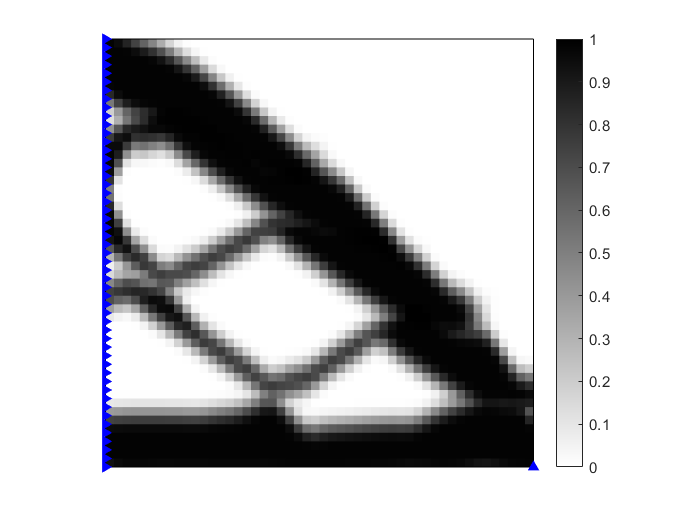

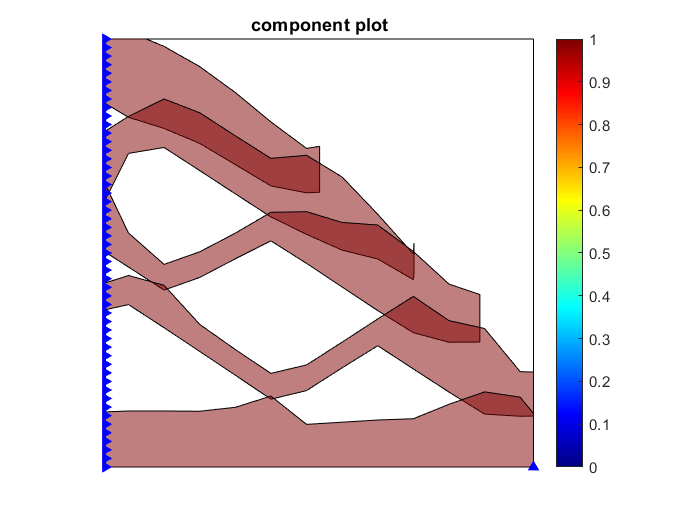

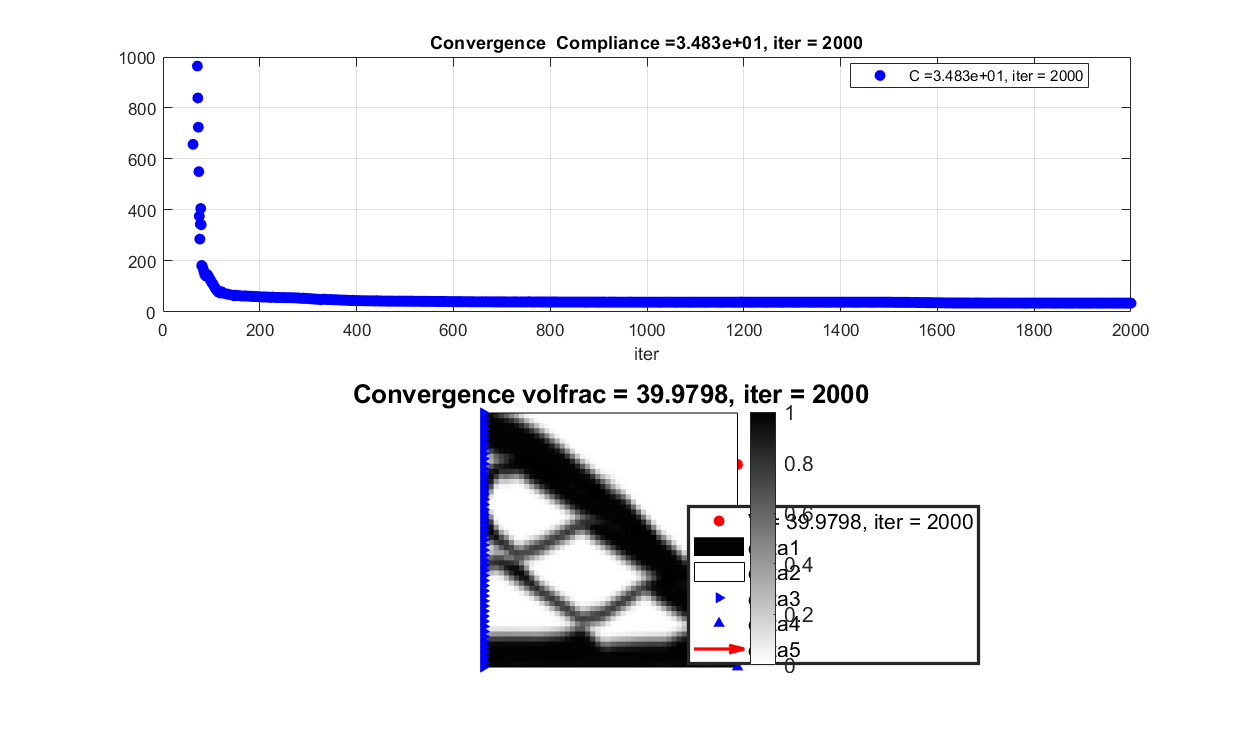

GGP_AM(50,50,0.4,'MBB','MNA',5,3,10,-pi/2,-10)